clear all

home_dir = 'D:/experiment_pics/';


## Extracting first echo from files

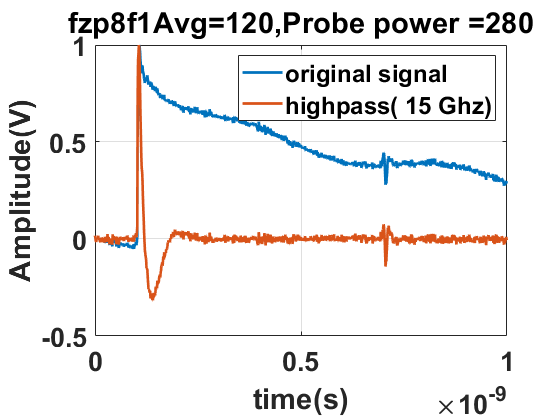

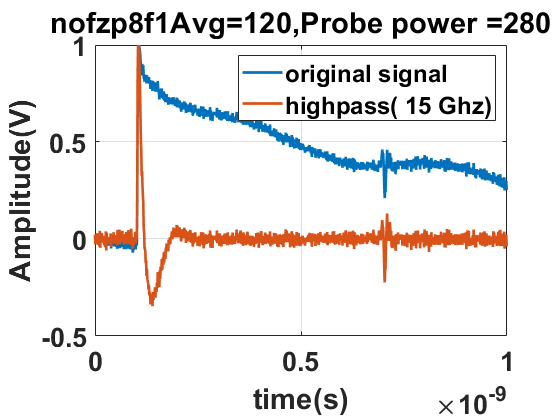

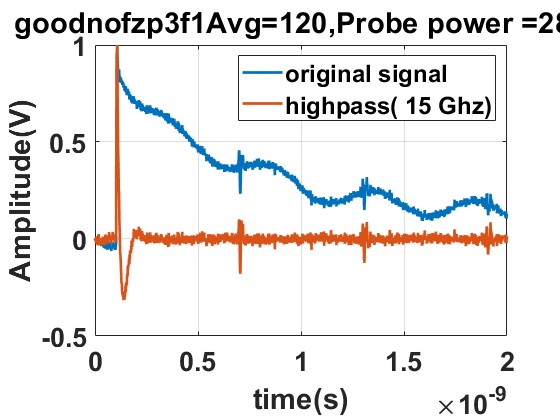

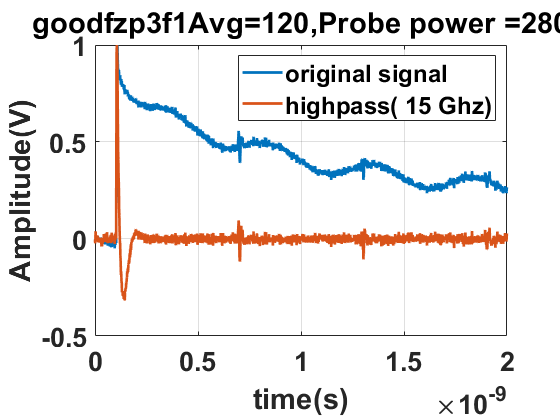

plotflag = 1;
date = '03_2022/21_03_22/';%'03_2022/25_03_22/';%'03_2022/21_03_22/';%'03_2022/22_03_22/';%'03_2022/22_03_22/';%'07_2022/11_07_22';
del_t = 0.5985e-9;
time_window_size = 0.30e-9/2;
count = 0;
norm = 1;
high_pass_cut_off = 15;
% Instructions for using extract_fitst_echo
% Input and output:
% [data,data_filt, first_echo_sig,error] =...
% extract_first_echo(home_dir,date,name,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,pos_name) 

fzp_sig = [];
no_fzp_sig = [];
count = 0;
switch date
   case '07_2022/11_07_22' 
       
    name_newconfig_pd2_s6_88mV_10win = 'newpd_peak88mVpower0p740mW_Navg60_10win';
    N_avg = 60;
    Probe_peak = 88;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multecho_noFZP_s6_newconfigpd2_88mV,multecho_noFZP_s6_newconfigpd2_filt_88mV,~,err_avg60_p740_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_88mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,high_pass_cut_off,'power=740\muW,');
       
    name_newconfig_pd2_s6_343mV_10win = 'newpd_peak343mVpower3p11mW_Navg120_10win';
    N_avg = 120;
    Probe_peak = 343;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multecho_noFZP_s6_newconfigpd2_343mV,multecho_noFZP_s6_newconfigpd2_filt_343mV,~,err_avg120_p3120_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_343mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,high_pass_cut_off,'power=3120\muW,');
        
    name_newconfig_pd2_s6_184mV_1win = 'newpd_peak184p3power1p65mW_Navg60_1win';
    N_avg = 60;
    Probe_peak = 184;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [echo_noFZP_s2_newconfigpd2_184mV,echo_noFZP_s2_newconfigpd2_filt_184mV,~,err_avg60_p1650_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_184mV_1win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,high_pass_cut_off,'power=1650\muW,');
        
    name_newconfig_pd2_s6_96mV_5win = 'newpd_peak96_Navg60_5win';
    N_avg = 60;
    Probe_peak = 96;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multechos_noFZP_s2_newconfigpd2_96mV,multechos_noFZP_s2_newconfigpd2_filt_96mV,~,err_avg60_p800_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_96mV_5win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,high_pass_cut_off,'power=800\muW,');
        
    name_newconfig_pd2_s6_96mV = 'newpd_peak96_Navg60_1win';
    N_avg = 60;
    Probe_peak = 96;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [echo_noFZP_s2_newconfigpd2_96mV,echo_noFZP_s2_newconfigpd2_filt_96mV,~,err_avg60_p750_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_96mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,high_pass_cut_off,'power=800\muW,');
    
   case '07_2022/08_07_22'     
    name_newconfig_pd2_s6_66mV = 'newpd_peak66_Navg60_5win';
    del_t = 0.659e-9;
    time_window_size = 0.50e-9/2;
    N_avg = 60;
    Probe_peak = 66;
    phase_selection =0;
    [multechos_noFZP_s2_newconfigpd2,multechos_noFZP_s2_newconfigpd2_filt,~,err_avg60_p550_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_66mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,high_pass_cut_off,'power=550\muW,');
    
    case '06_2022/16_06_22'
        name_noFZP_s2_multiple_echoes8 = 'nofzp_s5_480mV_60avg_4win';
        N_avg = 60;
        Probe_power = 480;
        [full_noFZP_multiple_echoes_8,full_noFZP_multiple_echoes_8_filt,first_echo_noFZP_multiple_echoes_8,err_avg_60_1] = ...
            extract_first_echo(home_dir,date,name_noFZP_s2_multiple_echoes8,del_t,time_window_size,1,...
            N_avg,Probe_power,0,high_pass_cut_off,'echoes:6');
        
    case '06_2022/15_06_22'     
    name_pump_fzp_old_config = 'fzp_oldconfig_multbody_572mV_60avg_5win';
    N_avg = 60;
    Probe_power = 572;
    phase_selection =0;
    norm = 0;
    [multechos_FZP_s2_old,multechos_FZP_s2_old_filt,~,err_avg60_1] = ...
        extract_first_echo(home_dir,date,name_pump_fzp_old_config,del_t,time_window_size,plotflag,...
        N_avg,Probe_power,norm,high_pass_cut_off,'old');
    

    
    case '06_2022/14_06_22'
        name_noFZP_s2_multiple_echoes6 = 'fzp_tip2_1y19x_multechoes_body_582mV_60avg_4win';
        N_avg = 100;
        Probe_power = 306.5;
        [full_noFZP_multiple_echoes_3,full_noFZP_multiple_echoes_3_filt,first_echo_noFZP_multiple_echoes_3,err_noFZP_multiple_echoes_3] = ...
            extract_first_echo(home_dir,date,name_noFZP_s2_multiple_echoes6,del_t,time_window_size,1,...
            N_avg,Probe_power,0,high_pass_cut_off,'echoes:6');
    
    case '05_2022/30_05_22'
        name_noFZP_s2_multiple_echoes = 'nofzp_tip2_testwobdd_3rd_echo_574mV_80avg_3win';
        N_avg = 100;
        Probe_power = 306.5;
        [full_noFZP_multiple_echoes_2,full_noFZP_multiple_echoes_2_filt,first_echo_noFZP_multiple_echoes_2,err_noFZP_multiple_echoes_2] = ...
            extract_first_echo(home_dir,date,name_noFZP_s2_multiple_echoes,del_t,time_window_size,1,...
            N_avg,Probe_power,0,high_pass_cut_off,'cantileverwobdd');
    
    case '05/2022/09_05_22'
        name_noFZP_s1_findingtip_16x = 'noFZP_findingtip1_16x_onTip_297p7mV_500avg_2win_sph205_282';
        [full_noFZP_s1_findingtip_16x,full_noFZP_s1_findingtip_16x_filt,~,~] = ...
            extract_first_echo_selected_phase(home_dir,date,name_noFZP_s1_findingtip_16x,del_t,time_window_size,1);
        
    case '05_2022/06_05_22'
        name_noFZP_findingtip_13x_2 = 'noFZP_findingtip_13x_onTip_306p5mV_100avg_4win';
        [full_noFZP_findingtip_13x_2,full_noFZP_findingtip_13x_2_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_13x_2,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_14x = 'noFZP_findingtip_14x_onTip_306p5mV_120avg_4win';
        [full_noFZP_findingtip_14x,full_noFZP_findingtip_14x_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_14x,del_t,time_window_size,...
            1,high_pass_cut_off);       

        
    
    case '05_2022/04_05_22'
        name_noFZP_findingtip_7_1 = 'noFZP_findingtip_7_onTip_281p5mV_30avg_1win';
        [full_noFZP_findingtip_7_1,full_noFZP_findingtip_7_1_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_7_1,del_t,time_window_size,...
            1,high_pass_cut_off);
        
        name_noFZP_findingtip_7_2 = 'noFZP_findingtip_7_onTip_281p5mV_15avg_1win';
        [full_noFZP_findingtip_7_2,full_noFZP_findingtip_7_2_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_7_2,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_8y = 'noFZP_findingtip_8y_onTip_290mV_15avg_1win';
        [full_noFZP_findingtip_8y,full_noFZP_findingtip_8y_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_8y,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_10y = 'noFZP_findingtip_10y_onTip_317mV_30avg_2win';
        [full_noFZP_findingtip_10y,full_noFZP_findingtip_10y_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_10y,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_11x = 'noFZP_findingtip_11x_onTip_287mV_30avg_2win';
        [full_noFZP_findingtip_11x,full_noFZP_findingtip_11x_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_11x,del_t,time_window_size,1,high_pass_cut_off);
        
         name_noFZP_findingtip_12y = 'noFZP_findingtip_12y_onTip_287mV_30avg_2win';
        [full_noFZP_findingtip_12y,full_noFZP_findingtip_12y_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_12y,del_t,time_window_size,1,high_pass_cut_off);
        
         name_noFZP_findingtip_13x = 'noFZP_findingtip_13x_onTip_284p5mV_30avg_4win';
        [full_noFZP_findingtip_13x,full_noFZP_findingtip_13x_filt,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_13x,del_t,time_window_size,1,high_pass_cut_off);
        
    case '05_2022/03_05_22'
        name_noFZP_findingtip_1 = 'noFZP_findingtip_1_onTip_306mV_60avg_2win';
        [full_noFZP_findingtip_1,~,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_1,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_2 = 'noFZP_findingtip_2_onTip_296mV_30avg_2win';
        [full_noFZP_findingtip_2,~,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_2,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_3 = 'noFZP_findingtip_3_onTip_296mV_60avg_2win';
        [full_noFZP_findingtip_3,~,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_3,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_4 = 'noFZP_findingtip_4_onTip_290mV_30avg_2win';
        [full_noFZP_findingtip_4,~,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_4,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_5 = 'noFZP_findingtip_5_onTip_290mV_30avg_2win';
        [full_noFZP_findingtip_5,~,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_5,del_t,time_window_size,1,high_pass_cut_off);
        
         name_noFZP_findingtip_6 = 'noFZP_findingtip_6_onTip_290mV_30avg_1win';
        [full_noFZP_findingtip_6,~,~,~] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_6,del_t,time_window_size,1,high_pass_cut_off);
        
         
        
    
    case '05_2022/02_05_22/'
        name_FZP_N18f12pt8_avg400 = 'FZPtip_3_onTip_394mV_360avg_4win';
        [full_FZP_N18f12pt8_avg400,full_FZP_N18f12pt8_filt_avg400,first_echo_FZP_N18f12pt8_avg400,err_full_FZP_N18f12pt8_avg400] = ...
            extract_first_echo(home_dir,date,name_FZP_N18f12pt8_avg400,del_t,time_window_size,1,high_pass_cut_off);
        
         name_noFZP_tip1_avg200 = 'FZPtip_1_onTip_296mV_200avg_4win';
        [full_noFZP_tip1_avg200,full_noFZP_tip1_avg200_filt,first_echo_noFZP_tip1_avg200,err_full_noFZP_tip1_avg200] = ...
            extract_first_echo(home_dir,date,name_noFZP_tip1_avg200,del_t,time_window_size,1,high_pass_cut_off);
        
        name_noFZP_findingtip_3  = 'noFZP_findingtip_3_onTip_296mV_60avg_2win';
        [full_noFZP_findingtip_3,full_noFZP_findingtip_3_filt,first_echo_noFZP_findingtip_3,err_full_noFZP_findingtip_3] = ...
            extract_first_echo(home_dir,date,name_noFZP_findingtip_3,del_t,time_window_size,1,high_pass_cut_off);
        
        
    case '04_2022/29_04_22/'
        name_no_FZP_neartip = 'FZPtip_3_nearTip_335';
        [full_noFZP_neartip,full_noFZP_neartip_filt,first_echo_noFZP_neartip,err_full_noFZP_neartip] = ...
            extract_first_echo(home_dir,date,name_no_FZP_neartip,del_t,time_window_size,1,high_pass_cut_off);
        
        name_FZP_N18f12pt8 = 'FZPtip_3_onTip_332mV_180avg_4win';
        [full_FZP_N18f12pt8,full_FZP_N18f12pt8_filt,first_echo_FZP_N18f12pt8,err_full_FZP_N18f12pt8] = ...
            extract_first_echo(home_dir,date,name_FZP_N18f12pt8,del_t,time_window_size,1,high_pass_cut_off);
        
        % Instructions for using extract_fitst_echo
% Input and output:
% [data,data_filt, first_echo_sig,error] =...
% extract_first_echo(home_dir,date,name,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,pos_name) 

        
    case '04_2022/14_04_2022/'
        name_no_FZP_many_echoes_old = 'pump_on_BDD_SmallerOpening_1';
        N_avg = 60;
        Probe_power = 500;
        [full_noFZP_many_echoes_old,full_noFZP_many_echoes_old_filt,first_echo_noFZP_many_echoes_old,err_full_noFZP_many_echoes_old] = ...
            extract_first_echo(home_dir,date,name_no_FZP_many_echoes_old,del_t,time_window_size,...
            plotflag,N_avg,Probe_power,norm,high_pass_cut_off,'mnay_echoes_old');
        
    case '03_2022/25_03_22/'
        name_noFZP_bad1f_nearbase = 'FZPcant_noFZP2_bad1Fnearbase_firstEcho_probe_power284_navg120_2windows';
        name_FZP_bad1f_nearbase = 'FZPcant_FZP2_bad1Fnearbase_firstEcho_probe_power284_navg120_2windows';
        N_avg = 120;
        Probe_power = 284;
%         [f_FZP_1f_nearbase,f_Sig_FZP_1f_nearbase] = take_fft(home_dir,date,name_FZP_bad1f_nearbase,del_t,time_window_size);
%         [f_noFZP_1f_nearbase,f_Sig_noFZP_1f_nearbase] = take_fft(home_dir,date,name_noFZP_bad1f_nearbase,del_t,time_window_size);
        
        [full_noFZP_bad1fnearbase,full_noFZP_bad1Fnearbase_filt,first_echo_noFZP_bad1fnearbase,err_full_noFZP_bad1fnearbase] =...
            extract_first_echo(home_dir,date,name_noFZP_bad1f_nearbase,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"noFZPbad1fnearbase");
        [full_FZP_bad1fnearbase,full_FZP_bad1Fnearbase_filt,first_echo_FZP_bad1fnearbase,err_full_FZP_bad1fnearbase] =...
            extract_first_echo(home_dir,date,name_FZP_bad1f_nearbase,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"FZPbad1fnearbase");
        
    case '03_2022/24_03_22/'
        name_noFZP_bad3F2 = 'FZPcant_noFZP2_bad3F_firstEcho_probe_power280_navg120_2windows';
        name_FZP_bad3F2 = 'FZPcant_FZP2_bad3F_firstEcho_probe_power282_navg120_2windows';
        
        name_noFZP_bad2F2 = 'FZPcant_noFZP2_bad2F_firstEcho_probe_power286_navg120_2windows';
        name_FZP_bad2F2 = 'FZPcant_FZP2_bad2F_firstEcho_probe_power282_navg120_2windows';
        
        name_noFZP_bad1F2 = 'FZPcant_noFZP2_bad1F_firstEcho_probe_power280_navg120_2windows';
        name_FZP_bad1F2 = 'FZPcant_FZP2_bad1F_firstEcho_probe_power287_navg120_2windows';
        
        [full_noFZP_bad3f2,full_noFZP_bad3F2_filt,first_echo_noFZP_bad3f2,err_full_noFZP_bad3f2] =...
            extract_first_echo(home_dir,date,name_noFZP_bad3F2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"noFZPbad3f2");
        [full_FZP_bad3f2,full_FZP_bad3F2_filt,first_echo_FZP_bad3f2,err_full_FZP_bad3f2] =...
            extract_first_echo(home_dir,date,name_FZP_bad3F2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"FZPbad3f2");
        
        [full_noFZP_bad2f2,full_noFZP_bad2F2_filt,first_echo_noFZP_bad2f2,err_full_noFZP_bad2f2] =...
            extract_first_echo(home_dir,date,name_noFZP_bad2F2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"noFZPbad2f2");
        [full_FZP_bad2f2,full_FZP_bad2F2_filt,first_echo_FZP_bad2f2,err_full_FZP_bad2f2] =...
            extract_first_echo(home_dir,date,name_FZP_bad2F2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"FZPbad2f2");
        
        [full_noFZP_bad1f2,full_noFZP_bad1F2_filt,first_echo_noFZP_bad1f2,err_full_noFZP_bad1f2] =...
            extract_first_echo(home_dir,date,name_noFZP_bad1F2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"noFZPbad1f2");
        [full_FZP_bad1f2,full_FZP_bad1F2,first_echo_FZP_bad1f2,err_full_FZP_bad1f2] =...
            extract_first_echo(home_dir,date,name_FZP_bad1F2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"FZPbad1f2");
        

        
    case '03_2022/23_03_22/'
        count = 1;
        name_noFZP_4Fbdd = 'FZPcant_noFZP2_4F_firstEcho_probe_power273_navg120_2windows_bdd0pt67';
        name_FZP_4Fbdd = 'FZPcant_FZP2_4F_firstEcho_probe_power274_navg120_2windows_bdd0pt68';
        
        [f_FZP,Sig_FZP] = take_fft(home_dir,date,name_FZP_4Fbdd,del_t,time_window_size);
        [full_FZP_4f,full_FZP_4f_filt,first_echo_FZP_4f,err_full_FZP_4f] = extract_first_echo(home_dir,date,name_FZP_4Fbdd,del_t,time_window_size,plotflag,norm,high_pass_cut_off);
        
        [f_noFZP,Sig_noFZP_4F] = take_fft(home_dir,date,name_noFZP_4Fbdd,del_t,time_window_size);
        [full_noFZP_4f,full_noFZP_4f_filt,first_echo_noFZP_4F,err_full_noFZP_4f] = extract_first_echo(home_dir,date,name_noFZP_4Fbdd,del_t,time_window_size,plotflag,norm,high_pass_cut_off);
              

        
    case '03_2022/22_03_22/'
        name_noFZP_8F_2 = 'FZPcant_noFZP2_8F_firstEcho_probe_power284_navg120_2windows';
        name_FZP_8F_2 = 'FZPcant_FZP2_8F_firstEcho_probe_power286_navg120_2windows';

        name_noFZP_2F_1 = 'FZPcant_noFZP1_2F_firstEcho_probe_power285_navg120_2windows';
        name_FZP_2F_1 = 'FZPcant_FZP1_2F_firstEcho_probe_power286_navg120_2windows';
        
        name_noFZP_4F_2 = 'FZPcant_noFZP2_4F_firstEcho_probe_power284_navg120_2windows';
        name_FZP_4F_2 = 'FZPcant_FZP2_4F_firstEcho_probe_power286pt5_navg120_2windows';
        N_avg = 120;
        Probe_power = 285;
        
%         [f_FZP_8F2,Sig_FZP_8F2] = take_fft(home_dir,date,name_FZP_8F_2,del_t,time_window_size);
        [full_FZP_8f2,full_FZP_8f2_filt,first_echo_FZP_8f2,err_full_FZP_8f2] = ...
            extract_first_echo(home_dir,date,name_FZP_8F_2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodFZP8f2");
        

        
%         [f_noFZP_8F2,Sig_noFZP_8F2] = take_fft(home_dir,date,name_noFZP_8F_2,del_t,time_window_size);
        [full_noFZP_8f2,full_noFZP_8f2_filt,first_echo_noFZP_8f2,err_full_noFZP_8f2] = ...
            extract_first_echo(home_dir,date,name_noFZP_8F_2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodnoFZP8f2");
        

        
        
%         [f_FZP_2F1,Sig_FZP_2F1] = take_fft(home_dir,date,name_FZP_2F_1,del_t,time_window_size);
        [full_FZP_2f1,full_FZP_2f1_filt,first_echo_FZP_2f1,err_full_FZP_2f1] = ...
            extract_first_echo(home_dir,date,name_FZP_2F_1,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodFZP2f1");
        
        
        
%         [f_noFZP_2F1,Sig_noFZP_2F1] = take_fft(home_dir,date,name_noFZP_2F_1,del_t,time_window_size);
        [full_noFZP_2f1,full_noFZP_2f1_filt,first_echo_noFZP_2f1,err_full_noFZP_2f1] =...
            extract_first_echo(home_dir,date,name_noFZP_2F_1,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodnoFZP2f1");
        

        
%         [f_FZP_4F2,Sig_FZP_4F2] = take_fft(home_dir,date,name_FZP_4F_2,del_t,time_window_size);        
        [full_FZP_4f2,full_FZP_4f2_filt,first_echo_FZP_4f2,err_full_FZP_4f2] =...
            extract_first_echo(home_dir,date,name_FZP_4F_2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodFZP4f2");
        
%         [f_noFZP_4F2,Sig_noFZP_4F2] = take_fft(home_dir,date,name_noFZP_4F_2,del_t,time_window_size);        
        [full_noFZP_4f2,full_noFZP_4f2_filt,first_echo_noFZP_4f2,err_full_noFZP_4f2] =...
            extract_first_echo(home_dir,date,name_noFZP_4F_2,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodnoFZP4f2");

        
    case '03_2022/21_03_22/'
        
        name_noFZP_8F_1 = 'FZPcant_noFZP1_8F_firstEcho_probe_power275_navg120_2';
        name_FZP_8F_1 = 'FZPcant_FZP1_8F_firstEcho_probe_power282_navg120';

        name_noFZP_3F_1 = 'FZPcant_noFZP1_3F_firstEcho_probe_power281_navg120_2windows';
        name_FZP_3F_1 = 'FZPcant_FZP1_3F_firstEcho_probe_power284_navg120_2windows';
        N_avg = 120;
        Probe_power = 280;

        
%         [f_FZP_8F1,Sig_FZP_8F1] = take_fft(home_dir,date,name_FZP_8F_1,del_t,time_window_size);
        [full_FZP_8f1,full_FZP_8f1_filt,first_echo_FZP_8f1,err_full_FZP_8f1] = ...
            extract_first_echo(home_dir,date,name_FZP_8F_1,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"fzp8f1");
        
%         [f_noFZP_8F1,Sig_noFZP_8F1] = take_fft(home_dir,date,name_noFZP_8F_1,del_t,time_window_size);
        [full_noFZP_8f1,full_noFZP_8f1_filt,first_echo_noFZP_8f1,err_full_noFZP_8f1] = ...
            extract_first_echo(home_dir,date,name_noFZP_8F_1,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"nofzp8f1");
        
%         [f_noFZP_3F1,Sig_noFZP_3F1] = take_fft(home_dir,date,name_noFZP_3F_1,del_t,time_window_size);
        [full_noFZP_3f1,full_noFZP_3f1_filt,first_echo_noFZP_3f1,err_full_noFZP_3f1] = ...
            extract_first_echo(home_dir,date,name_noFZP_3F_1,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodnofzp3f1");

%         [f_FZP_3F1,Sig_FZP_3F1] = take_fft(home_dir,date,name_FZP_3F_1,del_t,time_window_size);
        [full_FZP_3f1,full_FZP_3f1_filt,first_echo_FZP_3f1,err_full_FZP_3f1] = ...
            extract_first_echo(home_dir,date,name_FZP_3F_1,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,"goodfzp3f1");       
   

end

first_echo_good_fzps = {first_echo_FZP_2f1,first_echo_FZP_3f1,first_echo_FZP_4f2,first_echo_FZP_8f2};
first_echo_good_nofzps = {first_echo_noFZP_2f1,first_echo_noFZP_3f1,first_echo_noFZP_4f2,first_echo_noFZP_8f2};

full_good_fzps = {full_FZP_2f1,full_FZP_3f1,full_FZP_4f2,full_FZP_8f2};
therm_peak_good_fzps = [max(full_FZP_2f1(:,2)),max(full_FZP_3f1(:,2)),max(full_FZP_4f2(:,2)),max(full_FZP_8f2(:,2))];
full_good_nofzps = {full_noFZP_2f1,full_noFZP_3f1,full_noFZP_4f2,full_noFZP_8f2};
therm_peak_good_nofzps = [max(full_noFZP_2f1(:,2)),max(full_noFZP_3f1(:,2)),max(full_noFZP_4f2(:,2)),max(full_noFZP_8f2(:,2))];

first_echo_bad_fzps = {first_echo_FZP_bad1fnearbase,first_echo_FZP_bad1f2,first_echo_FZP_bad2f2,first_echo_FZP_bad3f2};

first_echo_bad_nofzps = {first_echo_noFZP_bad1fnearbase,first_echo_noFZP_bad1f2,first_echo_noFZP_bad2f2,first_echo_noFZP_bad3f2};


full_bad_fzps = {full_FZP_bad1fnearbase,full_FZP_bad1f2,full_FZP_bad2f2,full_FZP_bad3f2};
therm_peak_bad_fzps = [max(full_FZP_bad1fnearbase(:,2)),max(full_FZP_bad1f2(:,2)),max(full_FZP_bad2f2(:,2)),max(full_FZP_bad3f2(:,2))];
full_bad_nofzps = {full_noFZP_bad1fnearbase,full_noFZP_bad1f2,full_noFZP_bad2f2,full_noFZP_bad3f2};
therm_peak_bad_nofzps = [max(full_noFZP_bad1fnearbase(:,2)),max(full_noFZP_bad1f2(:,2)),max(full_noFZP_bad2f2(:,2)),max(full_noFZP_bad3f2(:,2))];

% txt = 'sin(\pi) = 0 \rightarrow';


## Plotting good FZPs vs no FZPs

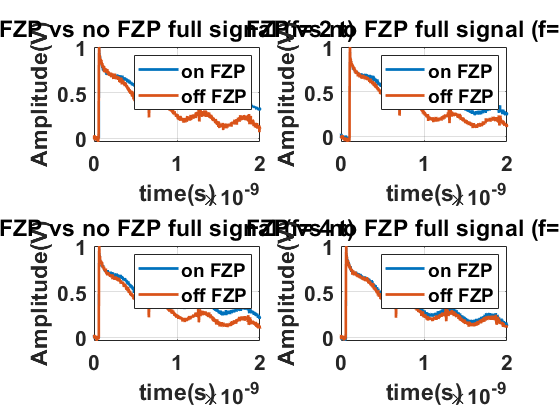

num = [ 2 3 4 8];

figure
for i=1:4
subplot(2,2,i)
plot(full_good_fzps{i}(:,1),full_good_fzps{i}(:,2)/therm_peak_good_fzps(i),...
    full_good_nofzps{i}(:,1),full_good_nofzps{i}(:,2)/therm_peak_good_nofzps(i),"Linewidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
legend(["on FZP" "off FZP"])
title(strjoin(["FZP vs no FZP full signal (f=" num2str(num(i)) "t)"]))
grid on
set(gca,'FontSize',16,'FontWeight','bold')
end


% subplot(2,2,2)
% plot(full_good_fzps{num}(:,1),full_good_fzps{num}(:,2),...
%     full_good_nofzps{num}(:,1),full_good_nofzps{num}(:,2),"Linewidth",2)
% xlabel("time(s)")
% ylabel("Amplitude(V)")
% legend(["on FZP" "off FZP"])
% title("First echo without 2Ghz disturbance (f=4t)")
% grid on
% set(gca,'FontSize',16,'FontWeight','bold')

## Plotting FFT of signals

figure
plot(f_FZP_1f_nearbase,abs(f_Sig_FZP_1f_nearbase),f_noFZP_1f_nearbase,abs(f_Sig_noFZP_1f_nearbase),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on 1f near base")
 legend(["On FZP " "Off FZP"])
grid on

figure
plot(f_FZP_8F2,abs(Sig_FZP_8F2),f_noFZP_8F2,abs(Sig_noFZP_8F2),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on and near 8F")
legend(["On FZP 8F" "Off FZP"])
grid on

plot(f_FZP_4F2,abs(Sig_FZP_4F2),f_noFZP_4F2,abs(Sig_noFZP_4F2),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on and near 4F")
legend(["On FZP 4F" "Off FZP"])
grid on

plot(f_FZP_3F1,abs(Sig_FZP_3F1),f_noFZP_3F1,abs(Sig_noFZP_3F1),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on and near 3F")
legend(["On FZP 3F" "Off FZP"])
grid on

plot(f_FZP_2F1,abs(Sig_FZP_2F1),f_noFZP_2F1,abs(Sig_noFZP_2F1),"LineWidth",2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on and near 2F")
legend(["On FZP 2F" "Off FZP"])
grid on
figure
plot(f_FZP_8F1,abs(Sig_FZP_8F1),f_noFZP_8F1,abs(Sig_noFZP_8F1),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on and near 8F near tip")
legend(["On FZP 8F" "Off FZP"])
grid on

## Fitting Radial Basis Functions dataset

NEWRB, neurons = 0, MSE = 0.000241424


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE           tStat         pValue  
                   ___________    _________    ___________    __________

    (Intercept)    -1.1013e-19    0.0006012    -1.8318e-16             1
    x1                 0.64472     0.038692         16.663    3.3236e-36


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.00748
R-squared: 0.645,  Adjusted R-Squared: 0.642
F-statistic vs. constant model: 278, p-value = 3.32e-36

NEWRB, neurons = 0, MSE = 0.0015282


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   ___________    _________    __________    __________

    (Intercept)    -1.0858e-18    0.0013255    -8.191e-16             1
    x1                 0.77219     0.033908        22.773    5.2301e-51


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0165
R-squared: 0.772,  Adjusted R-Squared: 0.771
F-statistic vs. constant model: 519, p-value = 5.23e-51

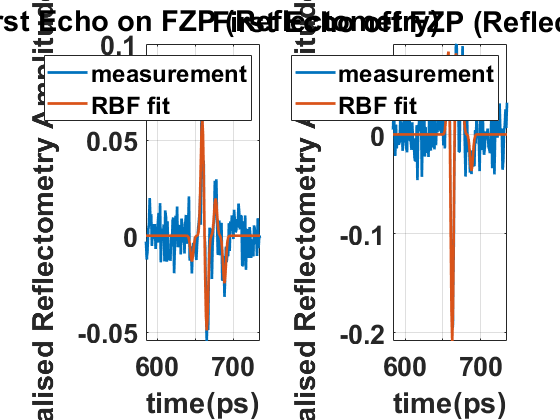

NEWRB, neurons = 0, MSE = 0.000721577


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE           tStat         pValue  
                   ___________    __________    ___________    __________

    (Intercept)    -7.4584e-20    0.00090836    -8.2108e-17             1
    x1                 0.77394      0.033816         22.887    2.8951e-51


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0113
R-squared: 0.774,  Adjusted R-Squared: 0.772
F-statistic vs. constant model: 524, p-value = 2.9e-51

NEWRB, neurons = 0, MSE = 0.00132342


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    _________    __________    __________

    (Intercept)    9.9453e-19    0.0010893    9.1301e-16             1
    x1                0.83589     0.029943        27.916    6.3801e-62


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0136
R-squared: 0.836,  Adjusted R-Squared: 0.835
F-statistic vs. constant model: 779, p-value = 6.38e-62

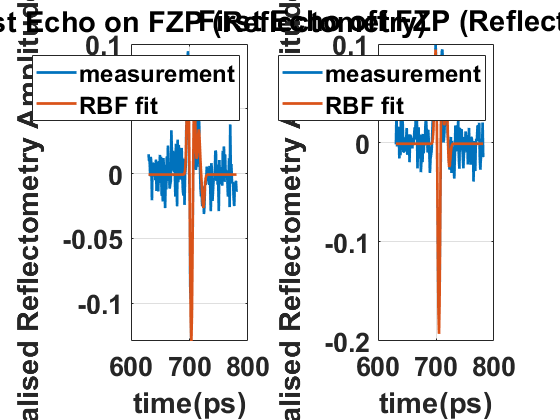

NEWRB, neurons = 0, MSE = 0.000772771


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE           tStat         pValue  
                   ___________    _________    ___________    __________

    (Intercept)    -3.9119e-19    0.0008831    -4.4297e-16             1
    x1                 0.80919     0.031768         25.472    6.6227e-57


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.011
R-squared: 0.809,  Adjusted R-Squared: 0.808
F-statistic vs. constant model: 649, p-value = 6.62e-57

NEWRB, neurons = 0, MSE = 0.0013274


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    _________    __________    __________

    (Intercept)    9.0165e-19    0.0010684    8.4391e-16             1
    x1                0.84413     0.029325        28.785    1.2344e-63


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0133
R-squared: 0.844,  Adjusted R-Squared: 0.843
F-statistic vs. constant model: 829, p-value = 1.23e-63

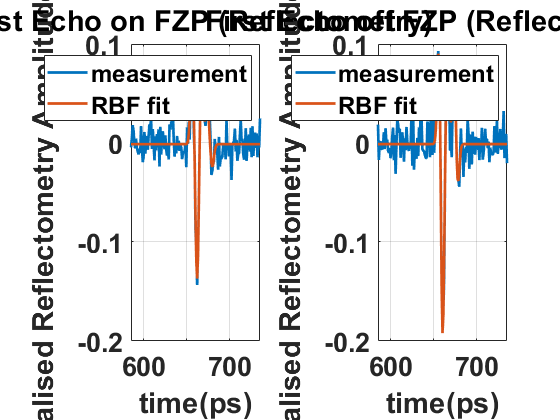

NEWRB, neurons = 0, MSE = 0.00118326


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    _________    __________    __________

    (Intercept)    5.3589e-19    0.0010404    5.1506e-16             1
    x1                 0.8317     0.030247        27.497    4.3959e-61


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.013
R-squared: 0.832,  Adjusted R-Squared: 0.831
F-statistic vs. constant model: 756, p-value = 4.4e-61

NEWRB, neurons = 0, MSE = 0.00137768


regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -5.7378e-19    0.001073    -5.3473e-16             1
    x1                 0.84947    0.028909         29.384    8.5456e-65


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0134
R-squared: 0.849,  Adjusted R-Squared: 0.848
F-statistic vs. constant model: 863, p-value = 8.55e-65

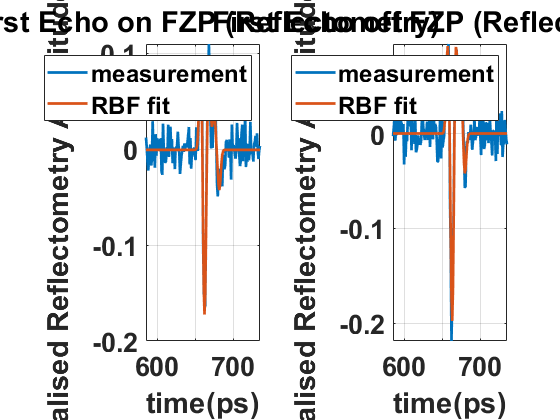

err_good_fzps = flip([err_full_FZP_8f2,err_full_FZP_4f2,err_full_FZP_3f1,err_full_FZP_2f1]);
err_good_nofzps = flip([err_full_noFZP_8f2,err_full_noFZP_4f2,err_full_noFZP_3f1,err_full_noFZP_2f1]);

goal_nn = 1e-15; % setting the mean-square error
spread = 0.226e-11;
mn = 5;
df = 25; % default
% t_data = t_FZP_bad1f2; % t_noFZP_8f2];
% Sig_noFZP = first_echo_FZP_8f2; % tSig_noFZP_8f2];
lower_time = [6.4 6.8 6.4 6.4]*1e-10;
upper_time = [6.9 7.3 6.9 6.9]*1e-10;
for i=1:numel(first_echo_good_fzps)
    [Sig_rbf_FZP{i},Sig_rbf_high_res_FZP{i},regression_FZP,p_to_p_sig_FZP(i),model_param_FZP{i}(:)] =...
        radial_basis_nn_fit(first_echo_good_fzps{i},goal_nn,spread,mn,df,0,0,upper_time(i),lower_time(i));
    fzp_fit_se_vs_noise_se(i,:) = [regression_FZP.RMSE err_good_fzps(i)];
    
    
%     reg_coeff_no_FZP = regression_FZP.coefficients
    [Sig_rbf_noFZP{i},Sig_rbf_high_res_noFZP{i},regression_noFZP,p_to_p_sig_noFZP(i),model_param_noFZP{i}(:)] =...
        radial_basis_nn_fit(first_echo_good_nofzps{i},goal_nn,spread,mn,df,0,0,upper_time(i),lower_time(i));
    no_fzp_fit_se_vs_noise_se(i,:) = [regression_noFZP.RMSE err_good_nofzps(i)];
%     error(i) = (p_to_p_sig_FZP(i)/p_to_p_sig_noFZP(i))*(sqrt((err_good_fzps(i)/(p_to_p_sig_FZP(i)))^2 + ...
%         (err_good_nofzps(i)/(p_to_p_sig_noFZP(i)))^2));
%      errorbar(Sig_rbf_high_res_FZP{i}(:,1),Sig_rbf_high_res_FZP{i}(:,2),err_good_fzps(i)*ones(size(Sig_rbf_high_res_FZP{i},1),1));

    figure
        subplot(1,2,1)
        plot(first_echo_good_fzps{i}(1,:)/1e-12,first_echo_good_fzps{i}(2,:),"LineWidth",2)
        hold on    
        plot(Sig_rbf_FZP{i}(:,1)/1e-12,Sig_rbf_FZP{i}(:,2),"LineWidth",2)
        set(gca,'FontSize',20,'FontWeight','bold')
        xlabel("time(ps)")
        ylabel("Normalised Reflectometry Amplitude(\deltaR/R_{0})")
        legend(["measurement" "RBF fit"])
        title("First Echo on FZP (Reflectometry)")
        grid on
            
        subplot(1,2,2)
        plot(first_echo_good_nofzps{i}(1,:)/1e-12,first_echo_good_nofzps{i}(2,:),"LineWidth",2)
        hold on    
        plot(Sig_rbf_noFZP{i}(:,1)/1e-12,Sig_rbf_noFZP{i}(:,2),"LineWidth",2)
        set(gca,'FontSize',20,'FontWeight','bold')
        xlabel("time(ps)")
        ylabel("Normalised Reflectometry Amplitude(\deltaR/R_{0})")
        legend(["measurement" "RBF fit"])
         title("First Echo off FZP (Reflectometry)")
        grid on

end

NEWRB, neurons = 0, MSE = 0.000108847


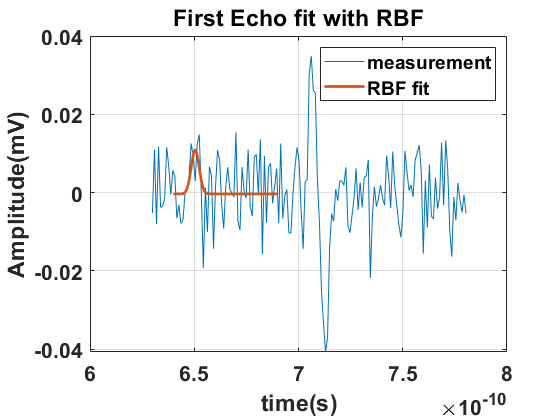

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   __________    __________    __________    __________

    (Intercept)    1.2344e-19    0.00042132    2.9299e-16             1
    x1                0.52186      0.040384        12.923    2.7119e-26


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.00525
R-squared: 0.522,  Adjusted R-Squared: 0.519
F-statistic vs. constant model: 167, p-value = 2.71e-26

NEWRB, neurons = 0, MSE = 0.00188627


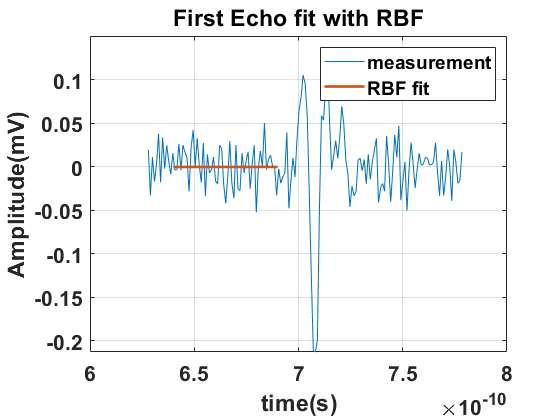

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE           tStat         pValue  
                   ___________    _________    ___________    __________

    (Intercept)    -1.5524e-18    0.0015171    -1.0233e-15             1
    x1                 0.75163      0.03493         21.518    3.9318e-48


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0189
R-squared: 0.752,  Adjusted R-Squared: 0.75
F-statistic vs. constant model: 463, p-value = 3.93e-48

NEWRB, neurons = 0, MSE = 0.00126637


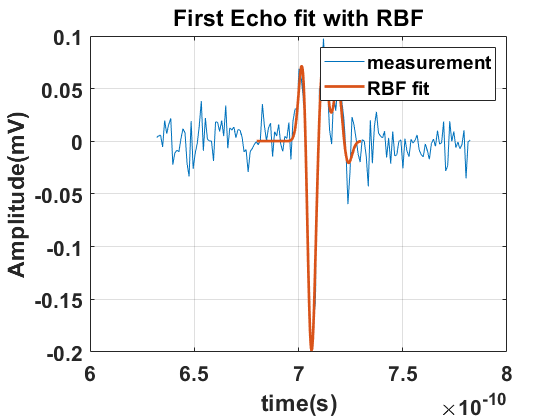

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE           tStat         pValue  
                   ___________    _________    ___________    __________

    (Intercept)    -1.3078e-18    0.0011373    -1.1499e-15             1
    x1                 0.80616     0.031958         25.225    2.2091e-56


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0142
R-squared: 0.806,  Adjusted R-Squared: 0.805
F-statistic vs. constant model: 636, p-value = 2.21e-56

NEWRB, neurons = 0, MSE = 0.00128841


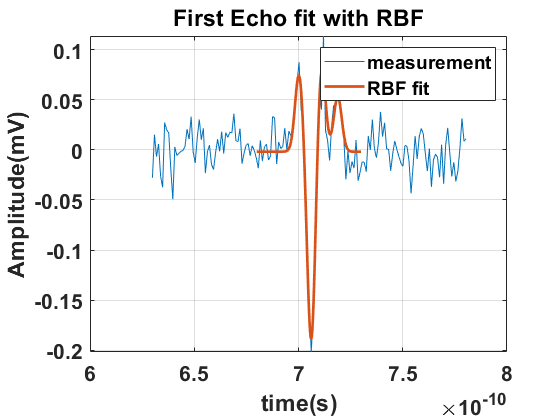

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE           tStat         pValue  
                   __________    _________    ___________    __________

    (Intercept)    -1.248e-18    0.0012135    -1.0284e-15             1
    x1                0.77407     0.033809         22.896    2.7677e-51


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0151
R-squared: 0.774,  Adjusted R-Squared: 0.773
F-statistic vs. constant model: 524, p-value = 2.77e-51

NEWRB, neurons = 0, MSE = 0.000895628


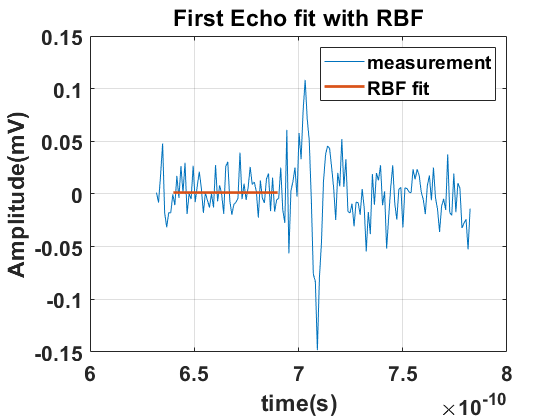

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE           tStat         pValue  
                   ___________    _________    ___________    __________

    (Intercept)    -2.8687e-19    0.0011857    -2.4194e-16             1
    x1                 0.59923     0.039619         15.125    3.4656e-32


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0148
R-squared: 0.599,  Adjusted R-Squared: 0.597
F-statistic vs. constant model: 229, p-value = 3.47e-32

NEWRB, neurons = 0, MSE = 0.00138307


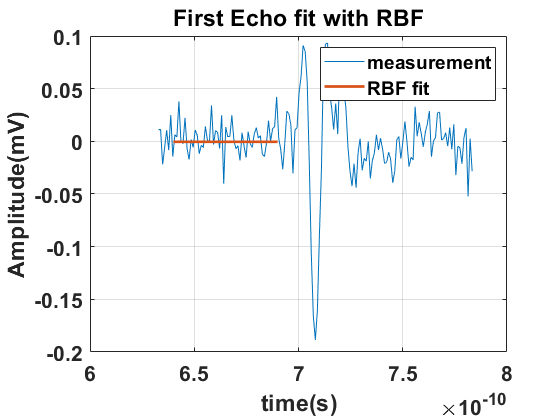

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE           tStat         pValue  
                   ___________    _________    ___________    __________

    (Intercept)    -2.2381e-18    0.0011643    -1.9223e-15             1
    x1                 0.81631     0.031306         26.075    3.5896e-58


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0145
R-squared: 0.816,  Adjusted R-Squared: 0.815
F-statistic vs. constant model: 680, p-value = 3.59e-58

NEWRB, neurons = 0, MSE = 0.000187475


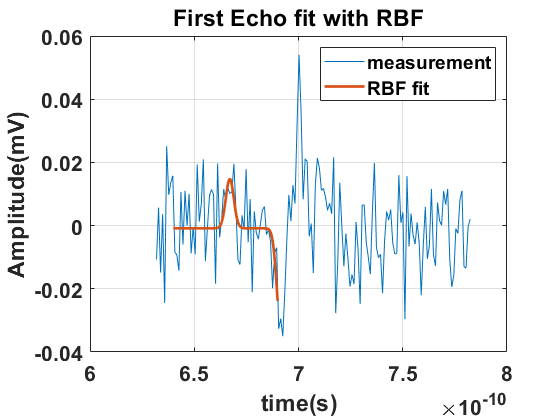

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    _________    __________    __________

    (Intercept)    6.9218e-19    0.0005437    1.2731e-15             1
    x1                0.40646     0.039709        10.236    4.6711e-19


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.00677
R-squared: 0.406,  Adjusted R-Squared: 0.403
F-statistic vs. constant model: 105, p-value = 4.67e-19

NEWRB, neurons = 0, MSE = 0.00127828


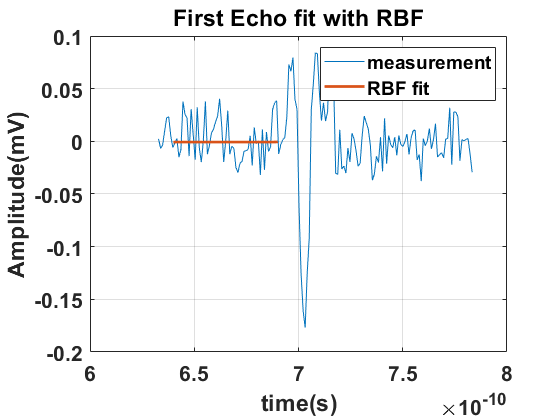

regression_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    _________    __________    __________

    (Intercept)    4.1676e-19    0.0012441    3.3498e-16             1
    x1                0.75443     0.034798         21.68    1.6515e-48


Number of observations: 155, Error degrees of freedom: 153
Root Mean Squared Error: 0.0155
R-squared: 0.754,  Adjusted R-Squared: 0.753
F-statistic vs. constant model: 470, p-value = 1.65e-48

save("D:/experiment_pics/fitted_echo_fzp_norm.mat",'Sig_rbf_high_res_FZP','-mat')
save("D:/experiment_pics/fitted_echo_nofzp_norm.mat",'Sig_rbf_high_res_noFZP','-mat')

err_badfzps = flip([err_full_FZP_bad3f2,err_full_FZP_bad2f2,err_full_FZP_bad1f2,err_full_FZP_bad1fnearbase]);
err_badnofzps =flip([err_full_noFZP_bad3f2,err_full_noFZP_bad2f2,err_full_noFZP_bad1f2,err_full_noFZP_bad1fnearbase]);

goal_nn = 1e-15; % setting the mean-square error
spread = 0.226e-11;
mn = 5;%[2 5 5 4 3 5 5 5];
df = 25; % default
for i=1:numel(first_echo_bad_fzps)
    [Sig_rbf_badFZP{i},Sig_rbf_high_res_badFZP{i},regression_badFZP,p_to_p_sig_badFZP(i),model_param_badFZP{i}(:)] =...
        radial_basis_nn_fit(first_echo_bad_fzps{i},goal_nn,spread,mn,df,1,0,upper_time(i),lower_time(i));
    badfzp_fit_se_vs_noise_se(i,:) = [regression_badFZP.RMSE err_badfzps(i)];
%     reg_coeff_no_FZP = regression_FZP.coefficients
    [Sig_rbf_badnoFZP{i},Sig_rbf_high_res_badnoFZP{i},regression_badnoFZP,p_to_p_sig_badnoFZP(i),model_param_badnoFZP{i}(:)] =...
        radial_basis_nn_fit(first_echo_bad_nofzps{i},goal_nn,spread,mn,df,1,0,upper_time(i),lower_time(i));
    badno_fzp_fit_se_vs_noise_se(i,:) = [regression_badnoFZP.RMSE err_badnofzps(i)];
%     error(i) = (p_to_p_sig_FZP(i)/p_to_p_sig_noFZP(i))*(sqrt((err_good_fzps(i)/(p_to_p_sig_FZP(i)))^2 + ...
%         (err_good_nofzps(i)/(p_to_p_sig_noFZP(i)))^2));
%      errorbar(Sig_rbf_high_res_FZP{i}(:,1),Sig_rbf_high_res_FZP{i}(:,2),err_good_fzps(i)*ones(size(Sig_rbf_high_res_FZP{i},1),1));
end

## Error Analysis

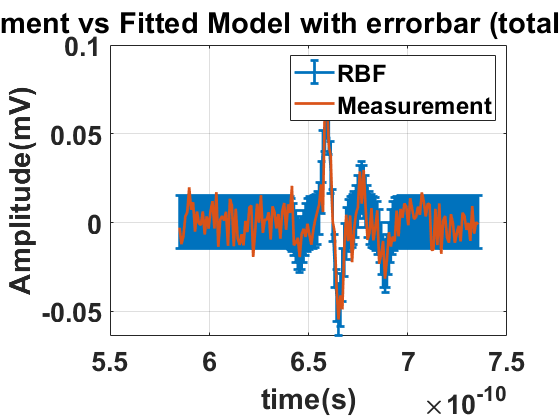

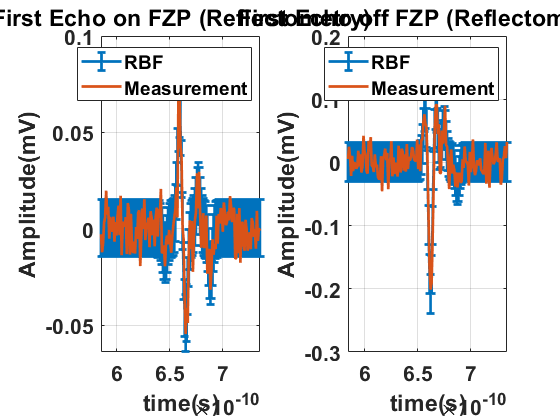

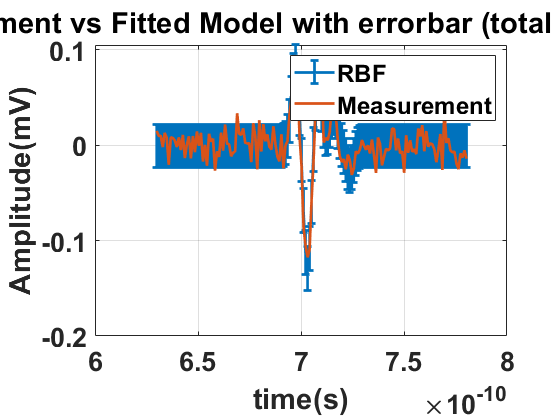

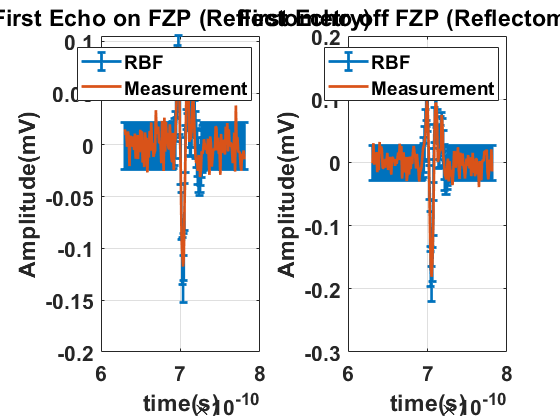

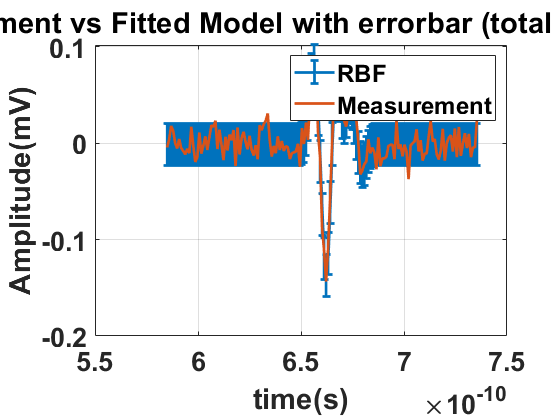

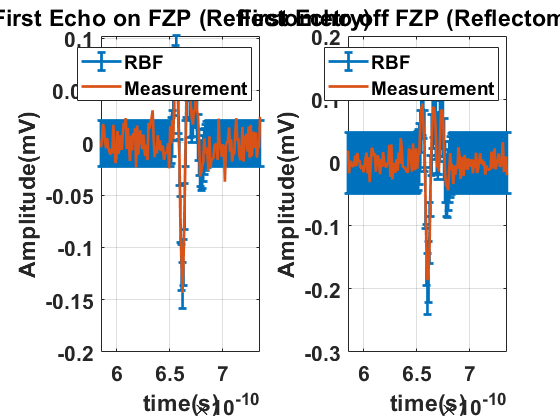

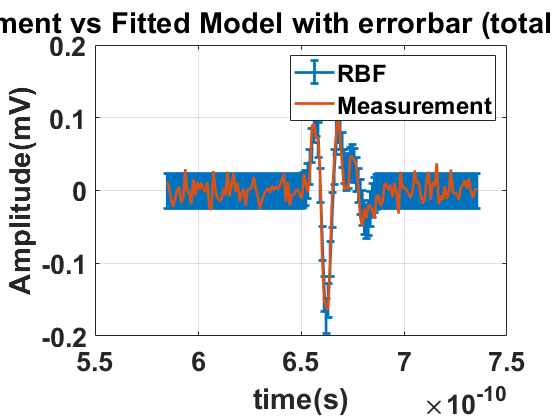

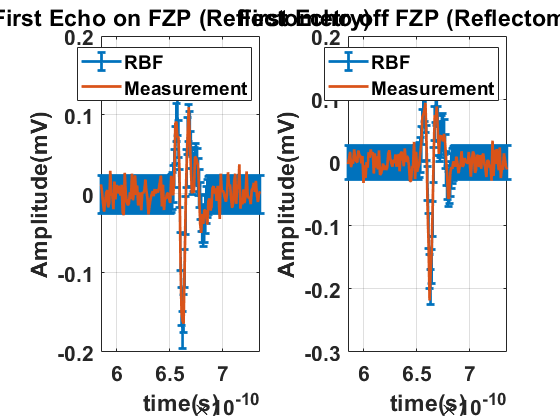

% Applying error propagation on smaller interval-size dataset
n_neurons = 5; % setting up number of basis functions
n_neurons_bad_fzp = [5 5 5 5 5 5 5 5];


for i=1:numel(Sig_rbf_high_res_FZP)
    [sigma_p_p(i),se_fit_parameters_FZP(:,i),se_fit_parameters_noFZP(:,i)] = ...
        error_propagation(Sig_rbf_FZP{i},Sig_rbf_noFZP{i},model_param_FZP{i},model_param_noFZP{i},err_good_fzps(i),err_good_nofzps(i),n_neurons,n_neurons);
    
    [sigma_p_p_badfzp(i),se_fit_parameters_badFZP(:,i),se_fit_parameters_badnoFZP(:,i)] = ...
        error_propagation(Sig_rbf_badFZP{i},Sig_rbf_badnoFZP{i},model_param_badFZP{i},model_param_badnoFZP{i},err_badfzps(i),err_badnofzps(i),n_neurons_bad_fzp(2*i-1),n_neurons_bad_fzp(2*i));

    %plotting dataset with errorbars on parameters
    figure
%     subplot(2,2,1)    
    errorbar(Sig_rbf_FZP{i}(:,1),Sig_rbf_FZP{i}(:,2),sum(se_fit_parameters_FZP(:,i))*ones(size(Sig_rbf_FZP{i},1),1),...
        "LineWidth",2);
    hold on
    plot(first_echo_good_fzps{i}(1,:),first_echo_good_fzps{i}(2,:),"Linewidth",2)
    set(gca,'FontSize',20,'FontWeight','bold')
    title("Measurement vs Fitted Model with errorbar (total uncertainty)")
    legend(["RBF" "Measurement"])
    xlabel("time(s)")
    ylabel("Amplitude(mV)")
    grid on
    
%     subplot(2,2,2)
%     errorbar(Sig_rbf_FZP{i}(:,1),Sig_rbf_FZP{i}(:,2),se_fit_parameters_FZP(3,i)*ones(size(Sig_rbf_FZP{i},1),1),...
%         "LineWidth",2);
%     hold on
%     plot(first_echo_good_fzps{i}(1,:),first_echo_good_fzps{i}(2,:),"Linewidth",2)
%        set(gca,'FontSize',16,'FontWeight','bold')
%     title("Errobar b2")
%     legend(["RBF" "Measurement"])
%     xlabel("time(s)")
%     ylabel("Amplitude(mV)")
%     grid on
%     
%     subplot(2,2,3)
%     errorbar(Sig_rbf_badFZP{i}(:,1),Sig_rbf_badFZP{i}(:,2),se_fit_parameters_badFZP(1,i)*ones(size(Sig_rbf_badFZP{i},1),1),...
%         "LineWidth",2);
%     hold on
%     plot(first_echo_bad_fzps{i}(1,:),first_echo_bad_fzps{i}(2,:),"Linewidth",2)
%        set(gca,'FontSize',16,'FontWeight','bold')
%     legend(["RBF" "Measurement"])
%     title("Errobar b2 for bad FZPs")
%     xlabel("time(s)")
%     ylabel("Amplitude(mV)")
%     grid on
%     
%     subplot(2,2,4)
%     errorbar(Sig_rbf_badFZP{i}(:,1),Sig_rbf_badFZP{i}(:,2),se_fit_parameters_badFZP(3,i)*ones(size(Sig_rbf_badFZP{i},1),1),...
%         "LineWidth",2);
%     hold on
%     plot(first_echo_bad_fzps{i}(1,:),first_echo_bad_fzps{i}(2,:),"Linewidth",2)
%        set(gca,'FontSize',16,'FontWeight','bold')
%     legend(["RBF" "Measurement"])
%     title("Errobar b2 for bad FZPs")
%     xlabel("time(s)")
%     ylabel("Amplitude(mV)")
%     grid on
    
    figure
    subplot(1,2,1)    
    errorbar(Sig_rbf_FZP{i}(:,1),Sig_rbf_FZP{i}(:,2),sum(se_fit_parameters_FZP(:,i))*ones(size(Sig_rbf_noFZP{i},1),1),...
        "LineWidth",2);
    hold on
    plot(first_echo_good_fzps{i}(1,:),first_echo_good_fzps{i}(2,:),"Linewidth",2)
       set(gca,'FontSize',16,'FontWeight','bold')
    title("First Echo on FZP (Reflectometry)")
    legend(["RBF" "Measurement"])
    xlabel("time(s)")
    ylabel("Amplitude(mV)")
    grid on
    
    subplot(1,2,2)    
    errorbar(Sig_rbf_noFZP{i}(:,1),Sig_rbf_noFZP{i}(:,2),sum(se_fit_parameters_noFZP(:,i))*ones(size(Sig_rbf_noFZP{i},1),1),...
        "LineWidth",2);
    hold on
    plot(first_echo_good_nofzps{i}(1,:),first_echo_good_nofzps{i}(2,:),"Linewidth",2)
       set(gca,'FontSize',16,'FontWeight','bold')
    title("First Echo off FZP (Reflectometry)")
    legend(["RBF" "Measurement"])
    xlabel("time(s)")
    ylabel("Amplitude(mV)")
    grid on
    
%     subplot(2,2,3)
%     errorbar(first_echo_good_fzps{i}(1,:),Sig_rbf_FZP{i},se_fit_parameters_FZP(6,i)*ones(size(Sig_rbf_FZP{i},2),1),...
%         "LineWidth",2);
%     title("Errobar b3")
%     xlabel("time(s)")
%     ylabel("Amplitude(mV)")
%     grid on
%     
%     subplot(2,2,4)
%     errorbar(first_echo_good_fzps{i}(1,:),Sig_rbf_FZP{i},se_fit_parameters_FZP(8,i)*ones(size(Sig_rbf_FZP{i},2),1),...
%         "LineWidth",2);
%     title("Errobar b4")
%     xlabel("time(s)")
%     ylabel("Amplitude(mV)")
%     grid on

end

## Saving data with error bars

f = [5.01312468004099 7.52435455205739 9.64262131507174 19.9177176301435];
f_badfzp = [2.5 2.5 5.01312468004099 7.52435455205739]

f_badfzp =     2.5000    2.5000    5.0131    7.5244


fzp_rbf_fit = [f;p_to_p_sig_FZP];

Unrecognized function or variable 'p_to_p_sig_FZP'.

no_fzp_rbf_fit = [f;p_to_p_sig_noFZP];
fzp_vs_no_fzp_rbf_fit = p_to_p_sig_FZP./p_to_p_sig_noFZP;
fitted_echoes_with_error_bar = [f;fzp_vs_no_fzp_rbf_fit;sigma_p_p];
% if norm==0
%     fzp_vs_no_fzp_rbf_fit_norm = (p_to_p_sig_FZP./therm_peak_good_fzps)./(p_to_p_sig_noFZP./(therm_peak_good_nofzps));
%     fitted_echoes_with_error_bar_norm = [f;fzp_vs_no_fzp_rbf_fit_norm;sigma_p_p];
% end

badfzp_vs_no_fzp_rbf_fit = p_to_p_sig_badFZP./p_to_p_sig_badnoFZP;
fitted_echoes_with_error_bar_badfzp = [f_badfzp;badfzp_vs_no_fzp_rbf_fit(1:end);sigma_p_p_badfzp(1:end)];
save("D:/experiment_pics/fitted_echo_amp_fzp_norm_hpf15.txt",'fzp_rbf_fit','-ascii')
save("D:/experiment_pics/fitted_echo_amp_nofzp_norm_hpf15.txt",'no_fzp_rbf_fit','-ascii')
save("D:/experiment_pics/fitted_echoes_with_error_bar_norm_hpf15.txt",'fitted_echoes_with_error_bar','-ascii')
save("D:/experiment_pics/fitted_echoes_with_error_bar_bad_fzp_norm_hpf15.txt",'fitted_echoes_with_error_bar_badfzp','-ascii')

## Plotting FZP/No/FZP signals

clear all
home_dir = 'D:/experiment_pics/';
cd(home_dir)

fzp_sim_echoes = load("reflectometry_sim_echoes_with_fzp_Al_corr_allzones_f7.txt");
no_fzp_sim_echoes = load("reflectometry_sim_echoes_without_fzp_Al_corr_allzones_f7.txt");

% fzp_sim_echoes_avg_param = load("reflectometry_sim_echoes_with_fzp_avg_param.txt");
% no_fzp_sim_echoes_avg_param = load("reflectometry_sim_echoes_without_fzp_avg_param.txt");

fzp_sim_echoes_norm = load("reflectometry_sim_echoes_with_fzp_norm_Al_corr_allzones_f7.txt");
no_fzp_sim_echoes_norm = load("reflectometry_sim_echoes_without_fzp_norm_Al_corr_allzones_f7.txt");

% fzp_sim_echoes_avg_param_norm = load("sim_echoes_with_fzp_avg_param_norm.txt");
% no_fzp_sim_echoes_avg_param_norm = load("sim_echoes_without_fzp_avg_param_norm.txt");

exp_echoes = load("fitted_echoes_with_error_bar.txt");
exp_echoes_norm = load("fitted_echoes_with_error_bar_norm.txt");
exp_echoes_bad_FZP = load("fitted_echoes_with_error_bar_bad_fzp.txt");
exp_echoes_norm_bad_FZP= load("fitted_echoes_with_error_bar_bad_fzp_norm.txt");


f = [5.01312468004099 7.52435455205739 9.64262131507174 19.9177176301435];
f_full = [2.5 5.01312468004099 7.52435455205739 9.64262131507174 19.9177176301435];

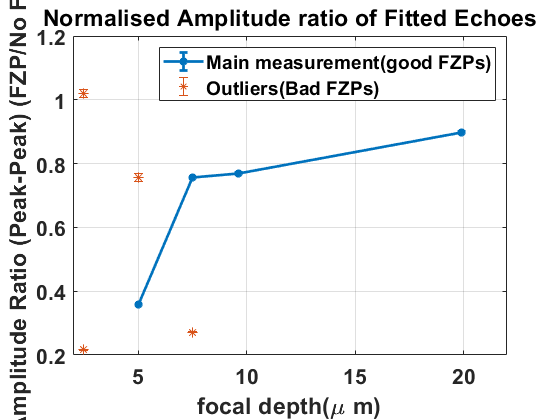


figure
% yyaxis left
errorbar(exp_echoes_norm(1,:),exp_echoes_norm(2,:),exp_echoes_norm(3,:),"LineWidth",2,"Marker","*")
hold on
errorbar(exp_echoes_norm_bad_FZP(1,:),exp_echoes_norm_bad_FZP(2,:),3*exp_echoes_norm_bad_FZP(3,:),"LineStyle",'none',"Marker","*","MarkerSize",7)
ylabel("Amplitude Ratio (Peak-Peak) (FZP/No FZP)")
hold on
% yyaxis right
% plot(fzp_vs_no_fzp_sim_echoes(1,:),fzp_vs_no_fzp_sim_echoes(2,:)/no_fzp_echoes(1),"LineWidth",2,"Marker","*")
xlabel("focal depth(\mu m)")
% ylabel("Strain Integral Signal (FZP/No FZP)")
title("Normalised Amplitude ratio of Fitted Echoes")
% legend(["measurement" "simulation"])
set(gca,'FontSize',16,'FontWeight','bold')
legend(["Main measurement(good FZPs)" "Outliers(Bad FZPs)"])
 xlim([2,22])

grid on

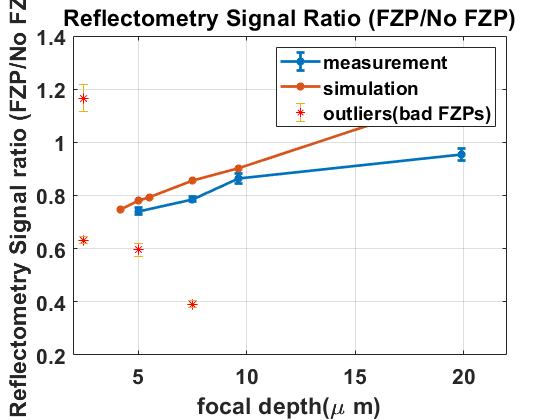



figure
% yyaxis left
errorbar(exp_echoes(1,:),exp_echoes(2,:),exp_echoes(3,:),"LineWidth",2,"Marker","*")
hold on
plot(fzp_sim_echoes(1,:),fzp_sim_echoes(2,:)/no_fzp_sim_echoes(1),"LineWidth",2,"Marker","*")
hold on
errorbar(exp_echoes_bad_FZP(1,:),exp_echoes_bad_FZP(2,:),exp_echoes_bad_FZP(3,:),"LineStyle",'none',...
    "Marker","*","MarkerSize",7,"MarkerEdgeColor","r")
hold on
ylabel("Reflectometry Signal ratio (FZP/No FZP)")
hold on
% yyaxis right
% plot(fzp_vs_no_fzp_sim_echoes(1,:),fzp_vs_no_fzp_sim_echoes(2,:)/no_fzp_echoes(1),"LineWidth",2,"Marker","*")
xlabel("focal depth(\mu m)")
% ylabel("Strain Integral Signal (FZP/No FZP)")
title("Reflectometry Signal Ratio (FZP/No FZP)")
legend(["measurement" "simulation" "outliers(bad FZPs)"])
set(gca,'FontSize',16,'FontWeight','bold')
 xlim([2,22])
grid on

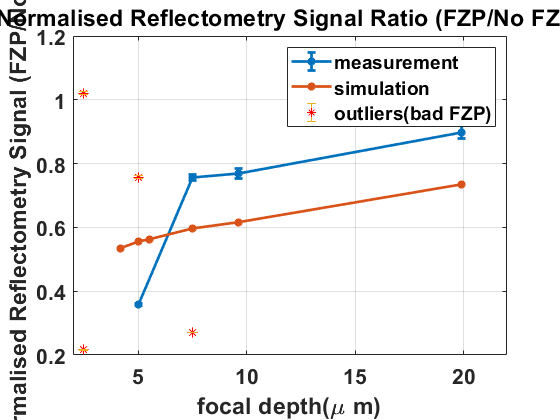

% figure
% 
% errorbar(exp_echoes(1,:),exp_echoes(2,:),exp_echoes(3,:),"LineWidth",2,"Marker","*")
% ylabel("Signal ratio (FZP/No FZP)")
% hold on
% plot(fzp_sim_echoes_avg_param(1,:),fzp_sim_echoes_avg_param(2,:)/no_fzp_sim_echoes_avg_param(1),"LineWidth",2,"Marker","*")
% xlabel("focal depth(\mu m)")
% ylabel("Strain Average Signal (FZP/No FZP)")
% title("Signal Ratio(FZP/No FZP) vs strain average ratio  from simulation")
% legend(["rbf_fit with errors" "dg-fem"])
% set(gca,'FontSize',16,'FontWeight','bold')
% grid on

figure
% yyaxis left
errorbar(exp_echoes_norm(1,:),exp_echoes_norm(2,:),9*exp_echoes_norm(3,:),"LineWidth",2,"Marker","*")
hold on
%
% plot(fzp_sim_echoes(1,:),fzp_sim_echoes(2,:)/no_fzp_sim_echoes(1),"LineWidth",2,"Marker","*")
plot(fzp_sim_echoes_norm(1,:),...
    fzp_sim_echoes_norm(2,:)/(no_fzp_sim_echoes_norm(1)/1.05),"LineWidth",2,"Marker","*")
hold on
errorbar(exp_echoes_norm_bad_FZP(1,:),exp_echoes_norm_bad_FZP(2,:),exp_echoes_norm_bad_FZP(3,:),...
    "LineStyle",'none',"Marker","*","MarkerSize",7,"MarkerEdgeColor","r")
hold on
ylabel("Reflectometry signal ratio (FZP/No FZP)")
hold on
% yyaxis right
xlabel("focal depth(\mu m)")
ylabel("Normalised Reflectometry Signal (FZP/No FZP)")
title("Normalised Reflectometry Signal Ratio (FZP/No FZP)")
legend(["measurement" "simulation" "outliers(bad FZP)"])
set(gca,'FontSize',16,'FontWeight','bold')
 xlim([2,22])
grid on

% figure
% errorbar(exp_echoes_norm(1,:),exp_echoes_norm(2,:),exp_echoes_norm(3,:),"LineWidth",2,"Marker","*")
% hold on
% plot(fzp_vs_no_fzp_sim_echoes_avg_param_norm(1,:),...
%     fzp_vs_no_fzp_sim_echoes_avg_param_norm(2,:)/no_fzp_sim_echoes_avg_param_norm(1),"LineWidth",2,"Marker","*")
% xlabel("focal depth(\mu m)")
% ylabel("Strain Integral Signal (FZP/No FZP)")
% title("Normalised Reflectometry Ratio vs Strain Integral ratio(FZP/No FZP)")
% legend(["measurement" "simulation"])
% set(gca,'FontSize',16,'FontWeight','bold')
% grid on

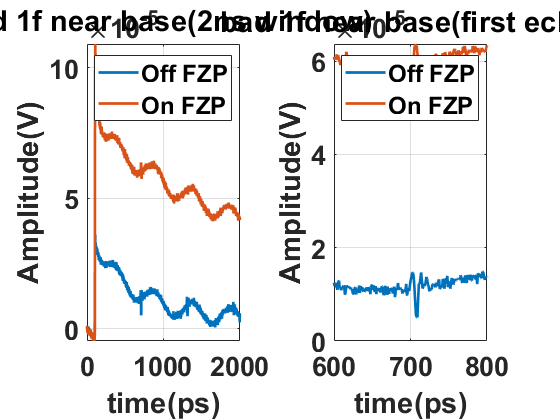

figure
subplot(1,2,1)
plot(full_noFZP_bad1fnearbase(:,1)/1e-12,full_noFZP_bad1fnearbase(:,2),full_FZP_bad1fnearbase(:,1)/1e-12,full_FZP_bad1fnearbase(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
title("bad 1f near base(2ns window)")
set(gca,'FontSize',20,'FontWeight','bold')
grid on
subplot(1,2,2)
plot(full_noFZP_bad1fnearbase(:,1)/1e-12,full_noFZP_bad1fnearbase(:,2),full_FZP_bad1fnearbase(:,1)/1e-12,full_FZP_bad1fnearbase(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
xlim([600 800])
title("bad 1f near base(first echo)")
set(gca,'FontSize',20,'FontWeight','bold')
grid on

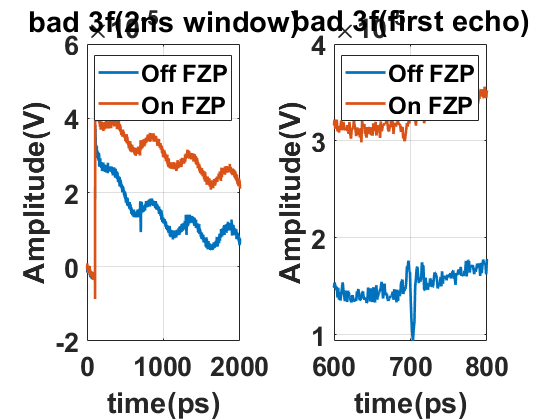


figure
subplot(1,2,1)
plot(full_noFZP_bad3f2(:,1)/1e-12,full_noFZP_bad3f2(:,2),full_FZP_bad3f2(:,1)/1e-12,full_FZP_bad3f2(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
title("bad 3f(2ns window)")
set(gca,'FontSize',20,'FontWeight','bold')
grid on
subplot(1,2,2)
plot(full_noFZP_bad3f2(:,1)/1e-12,full_noFZP_bad3f2(:,2),full_FZP_bad3f2(:,1)/1e-12,full_FZP_bad3f2(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
title("bad 3f(first echo)")
xlim([600 800])
set(gca,'FontSize',20,'FontWeight','bold')
grid on

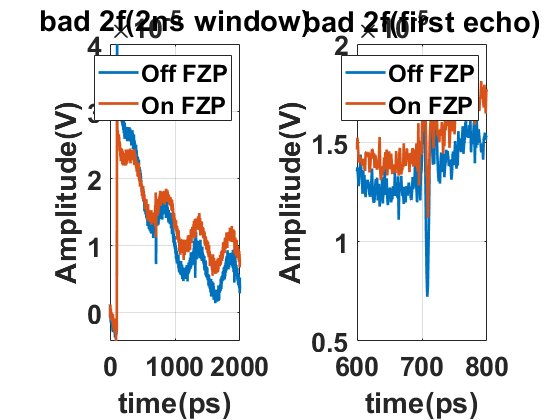


figure
subplot(1,2,1)
plot(full_noFZP_bad2f2(:,1)/1e-12,full_noFZP_bad2f2(:,2),full_FZP_bad2f2(:,1)/1e-12,full_FZP_bad2f2(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
title("bad 2f(2ns window)")

set(gca,'FontSize',20,'FontWeight','bold')
grid on
subplot(1,2,2)

plot(full_noFZP_bad2f2(:,1)/1e-12,full_noFZP_bad2f2(:,2),full_FZP_bad2f2(:,1)/1e-12,full_FZP_bad2f2(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
title("bad 2f(first echo)")
xlim([600 800])
set(gca,'FontSize',20,'FontWeight','bold')
grid on

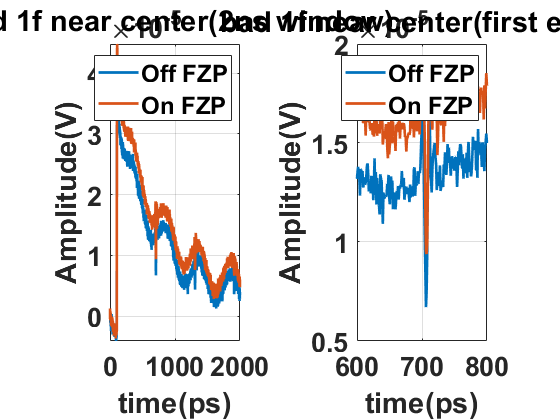


figure
subplot(1,2,1)
plot(full_noFZP_bad1f2(:,1)/1e-12,full_noFZP_bad1f2(:,2),full_FZP_bad1f2(:,1)/1e-12,full_FZP_bad1f2(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
legend(["Off FZP" "On FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
title("bad 1f near center(2ns window)")
grid on
subplot(1,2,2)
plot(full_noFZP_bad1f2(:,1)/1e-12,full_noFZP_bad1f2(:,2),full_FZP_bad1f2(:,1)/1e-12,full_FZP_bad1f2(:,2)...
    ,'LineWidth',2)
xlabel("time(ps)")
ylabel("Amplitude(V)")
set(gca,'FontSize',20,'FontWeight','bold')
legend(["Off FZP" "On FZP"])
xlim([600 800])
title("bad 1f near center(first echo)")
grid on

## Checking regression parameters

spread = 1e-11*linspace(0.1,0.56,30);
for i=1:size(spread,2)
    [Sig_rbf_noFZP_8F2,Sig_rbf_high_res_noFZP_8F2,tSig_rbf_high_res_noFZP_8F2,regression_noFZP_8F2] = radial_basis_nn_fit(t_data,Sig_noFZP',goal_nn,spread(i),mn,df,0,0);
    RMSE_fit(i) = regression_noFZP_8F2.RMSE;
    rsq_ord_fit(i) = regression_noFZP_8F2.Rsquared.Ordinary;
    rsq_adj_fit(i) = regression_noFZP_8F2.Rsquared.Adjusted;
    sse_fit(i) = regression_noFZP_8F2.SSE;
end
figure
plot(spread,RMSE_fit,"LineWidth",2)
xlabel("spread(s)")
ylabel("RMSE fit")
title("RMSE fit vs RBF spread")
grid on
figure
plot(spread,sse_fit,"LineWidth",2)
xlabel("spread(s)")
ylabel("SSE fit")
title("SSE fit vs RBF spread")
grid on

figure
plot(spread,rsq_ord_fit,spread,rsq_adj_fit,"LineWidth",2)
xlabel("spread(s)")
ylabel("R-squared fit")
title("R-squared fit vs RBF spread")
legend(["Ordinary" "Adjusted"])
grid on

## Noise level estimation vs amplitude of echo

c_p_si = 8433; % speed of sound in Si
tot_height = 15;
pump_spot_size = 4.7;
base_size = 5;
first_echo_time = 0.5985e-9;
time_window_size = 0.24e-9/2;

second_echo_time = 2*first_echo_time;
third_echo_time = 3*first_echo_time;
del_t = (second_echo_time+third_echo_time)/2;
% time_window_size = (third_echo_time-second_echo_time)-(0.5e-10);

data =  full_noFZP_8f2_filt;

Unrecognized function or variable 'full_noFZP_8f2_filt'.

%  se = err_full_noFZP_many_echoes_old;

[first_echo_time_sig,first_echo_sig_zero_mean] = extract_window(data(:,1),data(:,2),first_echo_time,time_window_size);
% [first_echo_max,ind_first_echo] = max(abs(first_echo_sig_zero_mean));
% t_first_echo = data(ind_first_echo,1);
% peak_peak_first_echo = max(first_echo_sig_zero_mean) - min(first_echo_sig_zero_mean);
[second_echo_time_sig,second_echo_sig_zero_mean] = extract_window(data(:,1),data(:,2),second_echo_time,time_window_size);

[third_echo_time_sig,third_echo_sig_zero_mean] = extract_window(data(:,1),data(:,2),third_echo_time,time_window_size);
echos = {[first_echo_time_sig,first_echo_sig_zero_mean],[second_echo_time_sig,second_echo_sig_zero_mean],[third_echo_time_sig,third_echo_sig_zero_mean]};
[echo_intensity,scaled_first_intensity,echo_times] = noise_level_vs_first_echo(c_p_si,tot_height,pump_spot_size,base_size,data,echos);

## Comparing echo amplitude at cantilever body with noise level experimental data

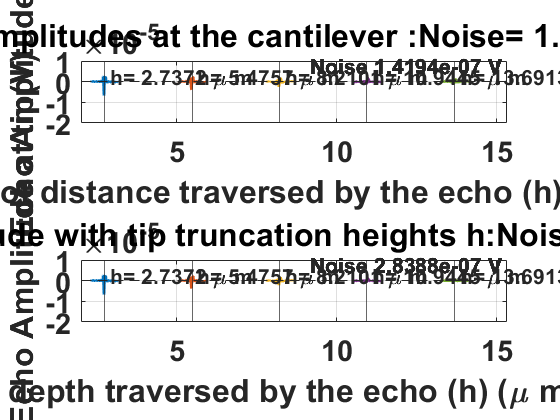

data = multecho_noFZP_s6_newconfigpd2_filt_88mV;%full_noFZP_multiple_echoes_8_filt; %full_noFZP_8f2_filt;
se = err_avg60_p740_pd2;%err_avg120_p3120_pd2;
N_avg = 60;
c_p_si = 8433;
tot_height = 14.5;
pump_spot_size = 4.5/2;
base_size = 5;
first_echo_rough_time = 0.65e-9;%0.589e-9;

rough_echo_time = [1 2 3 4 5 6 7]*first_echo_rough_time;% change this with number of echoes

% therm_peak_time = 2.93e-10;
% rough_echo_time_pos = [7.7254e-10, 1.262e-9, 1.75115e-9, 2.2405e-9, 2.72781e-9, 3.21712e-9, 3.70643e-9, 4.20941e-9, 4.68602e-9];
% rough_echo_time = rough_echo_time_pos - therm_peak_time;
time_window_size = 0.4e-9/2;

figure
num_echoes = 7;
for i=1:size(rough_echo_time,2)
%     rough_echo_time(i) = i*first_echo_time;
    [echo_time,echo_sig_zero_mean] =...
        extract_window(data(:,1),data(:,2),rough_echo_time(i),time_window_size);
    echos{i} = [echo_time,echo_sig_zero_mean]; 
    
    
%     plot (echos{i}(:,1),echos{i}(:,2))
%     grid on
%     hold on
end

% Scaling the intensity at the tip by rough calculation
[echo_intensity,scaled_first_intensity,scaled_amp,echo_times,tip_height] = noise_level_vs_first_echo_expdata(c_p_si,tot_height,pump_spot_size,base_size,...
    data,echos,se,N_avg);

% save("D:/experiment_pics/10echoes_for_attenuation_newconfig_pd2.mat",'echos')
% save("D:/experiment_pics/10echoes_for_attenuation_heights_newconfig_pd2.mat",'tip_height')

## Extracting 2 GHZ noise from signal

dataset(:,:,1) = [full_t_noFZP_3f1',full_noFZP_3f1_filt];

Unrecognized function or variable 'full_t_noFZP_3f1'.

dataset(:,:,2) = [full_t_noFZP_4f2',full_noFZP_4f2_filt];
dataset(:,:,3) = [full_FZP_4f',full_Sig_FZP_4F];
dataset(:,:,4) = [full_noFZP_bad3f2',full_noFZP_bad3F2];
dataset(:,:,5) = [full_noFZP_bad1fnearbase',full_noFZP_bad1Fnearbase_filt];

start_phase = (pi/180)*[261 66 318 101 316];
first_echo_time = 0.5985e-9;
second_echo_time = 2*first_echo_time;
third_echo_time = 3*first_echo_time;
del_t = (second_echo_time+third_echo_time)/2;
time_window_size = (third_echo_time-second_echo_time)-(0.5e-10);

for i=1:size(dataset,3)
    [t_noFZP(:,:,i),tSig_noFZP(:,:,i)] = extract_window(dataset(:,1,i),dataset(:,2,i),del_t,time_window_size);
    ang_noFZP(:,:,i) = (4*pi/(10e-9)) * (t_noFZP(:,:,i));
    % model_fit = 5.15e-6*(sin((2*pi*1.81e9)*(t_noFZP_8f_bad_disturb) - 0.9134));
    %  figure
    %  plot(t_noFZP_8f_bad_disturb,tSig_noFZP_8f_bad_disturb);%,t_noFZP_8f_bad_disturb,model_fit);
    %  grid on

    [f(i),ph(i),Amp(i),mdl1] = fitsine(ang_noFZP(:,:,i),tSig_noFZP(:,:,i));
end

date = {'21/4' '22/4' '23/4' '24/4' '25/4'};
figure
X = categorical(date);
X = reordercats(X,date);
Y = [ph;start_phase];

scatter(X,Y,40,"filled")
legend(["phase on disturbance signal" "start phase"])
xlabel('date')
ylabel('phase in radians')
title('Phase on 2Ghz disturbance signal')

grid on

## Functions

function [f_sig, S_sig] = take_fft(home_dir,date,name,del_t,time_window_size)

    [~,~,first_echo_Sig] = extract_first_echo(home_dir,date,name,del_t,time_window_size,0,1); 
    
    first_echo_time_sig = first_echo_Sig(:,1);
    first_echo_sig = first_echo_Sig(:,2);
    
    pad_length = 4^nextpow2(length(first_echo_time_sig));
    
    f_sig = 0:1/(pad_length*(first_echo_time_sig(2)-first_echo_time_sig(1)))...
        :(1/(first_echo_time_sig(2)-first_echo_time_sig(1)))-1/(pad_length*(first_echo_time_sig(2)-first_echo_time_sig(1)));
        
    S_sig = fft(first_echo_sig,pad_length);   
      

end

function [data,data_filt, echo_location,error] = extract_first_echo_selected_phase(home_dir,date,name,plotflag,N_avg,Probe_power) 
    file = load([home_dir '/' date '/' name '.mat']);
    % Ext
    signal_windows = file.Ym2;
    signal_windows_time = file.tbis;
    data(:,2) = signal_windows(:,2);data_Sig = data(:,2);
    data(:,1) = signal_windows_time(:,2);data_time = data(:,1);
    
        % Filtering 2Ghz disturbance from the signal
    f_start = 1e9;
    f_end = 8e9;
    f_sampling = 1/(data(2,1)-data(1,1));
    data_filt(:,1) = data(:,1);
    
    band_stop_Filt = designfilt('bandstopiir','FilterOrder',2, ...
         'PassbandFrequency1',f_start,'PassbandFrequency2',f_end, ...
         'SampleRate',f_sampling);
    
    hpFilt = designfilt('highpassiir','FilterOrder',2, ...
         'PassbandFrequency',f_end,'PassbandRipple',0.2, ...
         'SampleRate',f_sampling);
%     fvtool(band_stop_Filt)
    
    %[data_filt(:,2)] = filter(band_stop_Filt,data(:,2));
    [data_filt(:,2)] = filter(hpFilt,data(:,2));
   
    if plotflag == 1
        figure
        plot(data(:,1),data(:,2),"LineWidth",2)
        hold on
        plot(data_filt(:,1),data_filt(:,2))
        ylabel("Amplitude(mV)")
        xlabel("time(s)")
        legend(["original signal" "highpass(8Ghz)"])
        set(gca,'FontSize',16,'FontWeight','bold')
        title(strjoin(["N_avg=" num2str(N_avg) ",Probe power =" num2str(Probe_power)],''))
        grid on
    end
end

function [data,data_filt, first_echo_sig,error] = extract_first_echo(home_dir,date,name,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,high_pass_cut_off,pos_name) 
    file = load([home_dir '/' date '/' name '.mat']);
    data(:,2) = file.Sig;data_Sig = data(:,2);
    data(:,1) = file.treal;data_time = data(:,1);
    
    % Normalising the data with the thermal peak
    if norm == 1
        data_norm(:,2) = data(:,2)/(max(data(:,2)));
        data_norm(:,1) = data(:,1);
        
    else 
        data_norm = data;
    end
    
    % Filtering 2Ghz disturbance from the signal
    f_start = 1e9;
    f_end = high_pass_cut_off*1e9;
    f_sampling = 1/(data(2,1)-data(1,1));
    data_filt(:,1) = data(:,1);
    
    band_stop_Filt = designfilt('bandstopiir','FilterOrder',2, ...
         'PassbandFrequency1',f_start,'PassbandFrequency2',f_end, ...
         'SampleRate',f_sampling);
    
    hpFilt = designfilt('highpassiir','FilterOrder',2, ...
         'PassbandFrequency',f_end,'PassbandRipple',0.2, ...
         'SampleRate',f_sampling);
%     fvtool(band_stop_Filt)
    
    %[data_filt(:,2)] = filter(band_stop_Filt,data(:,2));
    [data_filt(:,2)] = filter(hpFilt,data(:,2));
    
    % Normalising the filtered data with the thermal peak
    if norm == 1
        data_filt(:,2) = data_filt(:,2)/(max(data_filt(:,2)));
    end
   
    if plotflag == 1
        figure
        plot(data_norm(:,1),data_norm(:,2),"LineWidth",2)
        hold on
        plot(data_filt(:,1),data_filt(:,2),"LineWidth",2)
        ylabel("Amplitude(V)")
        xlabel("time(s)")
        legend(["original signal" strjoin(["highpass(" num2str(high_pass_cut_off) "Ghz)"])])
        set(gca,'FontSize',20,'FontWeight','bold')
        title(strjoin([pos_name "Avg=" num2str(N_avg) ",Probe power =" num2str(Probe_power)],''))
        grid on
    end
    
%     [data_filt(:,2),dig_filt] = bandstop(data(:,2),[f_start f_end], f_sampling);
    
    [th_peak,ind] = max(data_filt(:,2));
    
    [t_echo,t_echo_idx] = min(abs(data_time - (data_time(ind) + del_t)));    
    [t_echo_start,t_echo_start_idx] = min(abs(data_time - (data_time(ind) + del_t-(time_window_size/2))));
    [t_echo_end,t_echo_end_idx] = min(abs(data_time - (data_time(ind) + del_t+(time_window_size/2))));
    
    first_echo_sig(2,:) = data_filt(t_echo_start_idx:t_echo_end_idx,2);
    
    first_echo_sig(1,:) = data_filt(t_echo_start_idx:t_echo_end_idx,1);
    
    first_echo_sig(2,:) = first_echo_sig(2,:)-mean(first_echo_sig(2,:)); 
    
    [noise_window, error] = standard_error(data_filt(:,1),data_filt(:,2),del_t,time_window_size);
end

% extract_window- extracts the window around a central time point del_t and
% window size of time_window_size
function [first_echo_time_sig,first_echo_sig_zero_mean,model_param] = extract_window(data_time,data,del_t,time_window_size) 
%     file = load([home_dir '/' date '/' name '.mat']);
%     data = file.Sig;
%     data_time = file.treal;
    
    [th_peak,ind] = max(data);
    
    [t_echo,t_echo_idx] = min(abs(data_time - (data_time(ind) + del_t)));    
    [t_echo_start,t_echo_start_idx] = min(abs(data_time - (data_time(ind) + del_t-(time_window_size/2))));
    [t_echo_end,t_echo_end_idx] = min(abs(data_time - (data_time(ind) + del_t+(time_window_size/2))));
    
    first_echo_sig = data(t_echo_start_idx:t_echo_end_idx);
    
    first_echo_time_sig = data_time(t_echo_start_idx:t_echo_end_idx);
    
    first_echo_sig_zero_mean = first_echo_sig-mean(first_echo_sig); 
end

function [y_rbf_data_pts,y_rbf_high_res,regression_fit,peak_to_peak,model_param] = radial_basis_nn_fit(first_echo_Sig,goal,spread,mn,df,plotflag,viewnnflag,upper_time,lower_time)

    first_echo_time_sig = first_echo_Sig(1,:);
    first_echo_sig = first_echo_Sig(2,:);
% Create Radial Basis function Neural Network
% the fact that:
% Znn_rbf([x,y]) = Znn_rbf.LW{2,1}*exp((Znn_rbf.b{1}.*dist(Znn_rbf.IW{1},[x;y])).^2)+Znn_rbf.b{2}...
% f = b*exp((w*(t-c))^2)

% %     [first_echo_time_sig,first_echo_sig] = extract_first_echo(home_dir,date,name,del_t,time_window_size); 
%     
% %     norm_time_sig = normalize(first_echo_time_sig);
     net  = newrb(first_echo_time_sig,first_echo_sig,goal,spread,mn,df);%,mn,df);
     
%     net  = newrbe(first_echo_time_sig,first_echo_sig,spread); % RBF with exact neural network
%     net  = newgrnn(first_echo_time_sig,first_echo_sig,spread); % RBF with Generalised Neural network
%     net  = newpnn(first_echo_time_sig,first_echo_sig,spread);% RBF with Probabilistic Neural network
    model_param = {net.LW{2,1} net.IW{1} net.b{1}}; % parameters of the model
    
    if viewnnflag == true
        view(net);
    end
    
    y_rbf = net(first_echo_time_sig);%sim(net,first_echo_time_sig);
%     error = y_rbf - first_echo_sig;
    t_high_res = linspace(lower_time,upper_time,399);
    y_rbf_data_pts = [first_echo_time_sig' y_rbf'];
    y_rbf_high_res(:,2) = net(t_high_res);%sim(net,first_echo_time_sig);
    y_rbf_high_res(:,1) = t_high_res;
    peak_to_peak = max(y_rbf_high_res(:,2)) - min(y_rbf_high_res(:,2)); 
    
    [max_rbf,err_max_ind] = max(y_rbf);
    [min_rbf,err_min_ind] = min(y_rbf);
%     
%     peaks = [max_rbf min_rbf];
%     err_peaks = [error(err_max_ind) error(err_min_ind)];
% Plots
    if plotflag == true
        figure
        plot(first_echo_time_sig,first_echo_sig)
        hold on    
        plot(y_rbf_high_res(:,1),y_rbf_high_res(:,2),"LineWidth",2,"MarkerSize",10)
        set(gca,'FontSize',16,'FontWeight','bold')
        xlabel("time(s)")
        ylabel("Amplitude(mV)")
        legend(["measurement" "RBF fit"])
        title("First Echo fit with RBF")
        grid on
    end
    
%     if plotflag_err_bar == true
%         figure
%         errorbar(first_echo_time_sig,first_echo_sig,error)
%         hold on    
% %         plot(t_high_res,y_rbf_high_res,"LineWidth",2,"MarkerSize",10)
%         xlabel("time(s)")
%         ylabel("Amplitude(mV)")
%         title("First Echo with error bar")
%         grid on
%     end
    
    %regression_fit = regression(first_echo_sig,y_rbf);
    regression_fit = fitlm(first_echo_sig,y_rbf)
    
end

function [f,ph,Amp,mdl1] = fitsine(angle,sig)  
    
   pad_length = length(angle);
    f_sig = 0:1/(pad_length*(angle(2)-angle(1)))...
        :(1/(angle(2)-angle(1)))-1/(pad_length*(angle(2)-angle(1)));
        
    S_sig_fft = fft(sig);
    [~,max_sig_loc] = max(abs(S_sig_fft(1:pad_length/2)));
    f = f_sig(1,max_sig_loc)
    omega = 2*pi*f;
    
%     Amp = 4e-6;
    
    ft = fittype(@(ph,Amp, x)(sin((omega*(x - ph)))*Amp));%,'coefficients',{'ph','Amp'});
    mdl1 = fit(angle,sig,ft,'startpoint',[0.65,3e-6]);
    ph = mdl1.ph
%      f = mdl1.omega/(2*pi)
    mdl1.Amp = 4e-6;%abs(mdl1.Amp);
    Amp = mdl1.Amp
    
    figure
    plot(mdl1,angle,sig)
    grid on
    
end

function [noise_window, se] = standard_error(data_time,data,first_echo_time,first_echo_width)%,del_t,time_window_size)    
%     first_echo_time = 0.5985e-9;
    second_echo_time = 2*first_echo_time;
    third_echo_time = 3*first_echo_time;
    del_t = (first_echo_time+second_echo_time)/2;
    time_window_size = (second_echo_time-first_echo_time)-first_echo_width;
    
    [noise_window(1,:),noise_window(2,:)] = extract_window(data_time,data,del_t,time_window_size);
    
    se = std(noise_window(2,:));%*size(first_echo_sig,2);
%     se = max(noise_window(2,:)) - min(noise_window(2,:));
    
    
end



function [echo_intensity,scaled_echo_intensity,scaled_calculated_amp,echo_times,tip_height] = noise_level_vs_first_echo_expdata(c_p_si,tot_height,pump_spot_size,base_size,data,echos,se,Avg)
    
    [thermal_peak,ind_peak] = max(data(:,2));
    t_thermal_peak = data(ind_peak,1);
    echo_intensity = echos;
    scaled_echo_intensity = echos;
    reflec_coefficient = 0;%0.13;
  % Finding the attenuation factor, time and tip thickness  from the measurement data  
    figure
%     [noise_window, se] = standard_error(data(:,1),data(:,2));
    for i=1:numel(echos)   
        peak_peak(i) = max(echos{i}(:,2))-min(echos{i}(:,2)); % Taking minimum as amplitude instead of peak-peak
        [max_echo(i),ind_max_echo] = max(echos{i}(:,2));
        [min_echo(i),ind_min_echo] = min(echos{i}(:,2));
        echo_times(i) = echos{i}(ind_min_echo,1);%(echos{i}(ind_max_echo,1) + echos{i}(ind_min_echo,1))/2;
%         tip_height(i) = 1e6* c_p_si*(echo_times(i)-t_thermal_peak)/2;
%         tip_width(i) = base_size*(1-(tip_height(i)/tot_height));
        

%         figure
    end  
            
    % Extrapolating distance traversed, attenuation factor and calculated
    % attenuation amplitude with first echo as reference
   
    
    tip_thickness = 1e6* c_p_si*(echo_times(2:end)-echo_times(1:end-1))/2;
    echo_delt = echo_times(2:end)-echo_times(1:end-1); 
    tip_height = cumsum([mean(tip_thickness) tip_thickness]);
    tip_width = base_size*(1-((tip_height - mean(tip_thickness))/tot_height));
    alpha = -log(peak_peak(2:end)./peak_peak(1:end-1))./(2*(tip_height(2:end)-tip_height(1:end-1)));
    calculated_amp = peak_peak(1)*exp(-mean(alpha)*2*(tip_height-tip_height(1)));
    count = 1;
    
%     subplot(2,1,1)
%     plot(c_p_si*(echos{1}(:,1)-t_thermal_peak)/2,echos{1}(:,2),"LineWidth",2)
%     xlabel("distance traversed(m)")
%     ylabel("Echo Amplitude(V)")
%     yline([-se se],'--',{'Noise' 'Noise'})
%     grid on
%     set(gca,'FontSize',16,'FontWeight','bold')
%     title("rough echo intensity variation at different depths")
%     xline(tip_height(1)*1e-6,'-',{strjoin(["h=" num2str(tip_height(1))])})
%     hold on
%     
%     subplot(2,1,2)
%     plot(c_p_si*(scaled_echo_intensity{1}(:,1)-t_thermal_peak)/2,scaled_echo_intensity{1}(:,2),"LineWidth",2)
%     xlabel("distance traversed (m)")        
%     ylabel("Scaled Echo Amplitude at tip(V) ")
%     yline([-se se],'--',{'Noise' 'Noise'})
%     grid on
%     xline(tip_height(1)*1e-6,'-',{strjoin(["h=" num2str(tip_height(1))])})
%     hold on
%     title("rough echo intensity variation at different truncation depths at the tip")
%     set(gca,'FontSize',16,'FontWeight','bold')
%     
    while abs(peak_peak(count))>se 
        
        scaled_echo_intensity{count}(:,2) = scaled_echo_intensity{count}(:,2)*(gaussean_factor(tip_width(count),tip_width(1),pump_spot_size))/...
            ((1-reflec_coefficient)^(2*(count-1)));
        scaled_calculated_amp(count) = peak_peak(count)*(gaussean_factor(tip_width(count),tip_width(1),pump_spot_size));
%         scaled_echo_intensity{count+1}(:,1) = scaled_echo_intensity{count+1}(:,1) + (mean(echo_delt));
%         echo_times(count+1) = echo_times(count) + (mean(echo_delt));
        peak_peak(count) = max(scaled_echo_intensity{count}(:,2))-min(scaled_echo_intensity{count}(:,2));
        
        subplot(2,1,1)
        plot(c_p_si*1e6*(echos{count}(:,1)-t_thermal_peak)/2,echos{count}(:,2),"LineWidth",2)
        xlabel("half of distance traversed by the echo (h) (\mu m)")
        ylabel("Echo Amplitude(V)")
        yline(se,'--',{strjoin(["Noise" num2str(se) "V"])},"Fontsize",16,"FontWeight",'bold')
        yline(-se,'--')
        grid on
        set(gca,'FontSize',22,'FontWeight','bold')
       
        title(strjoin(["measured echo amplitudes at the cantilever :Noise=" num2str(se) "V,Avg=" num2str(Avg)]))
        xline(tip_height(count),'-',{strjoin(["h=" num2str(tip_height(count)) "\mu m"])},"Fontsize",16,"FontWeight",'bold','LabelOrientation','horizontal')
        xlim([2,0.8*tip_height(count)])
        ylim([-2e-5,1e-5])
        hold on
        
        subplot(2,1,2)
        plot(c_p_si*1e6*(scaled_echo_intensity{count}(:,1)-t_thermal_peak)/2,scaled_echo_intensity{count}(:,2),"LineWidth",2)
        xlabel("depth traversed by the echo (h) (\mu m)")        
        ylabel("Scaled Echo Amplitude at tip(V) ")
        yline(se ,'--', {strjoin(["Noise" num2str(2*se) "V"])},"Fontsize",16,"FontWeight",'bold')
        yline(-se ,'--')
        grid on
        xline(tip_height(count),'-',{strjoin(["h=" num2str(tip_height(count)) "\mu m"])},"Fontsize",16,"FontWeight",'bold','LabelOrientation','horizontal')
        hold on
        title(strjoin(["estimated echo amplitude with tip truncation heights h:Noise=" num2str(se) "V,Avg=" num2str(Avg)]))
        xlim([2,0.8*tip_height(count)])
        ylim([-2e-5,1e-5])
        set(gca,'FontSize',22,'FontWeight','bold')
        count = count+1;
        if count>numel(echos)
            break
        end
        end
      
  
    %Marking the desired amplitude for the height
%     subplot(2,1,1)
%     plot(tip_height*1e-6,calculated_amp,"LineWidth",2,"Marker","*")
%     text(tip_height(1),calculated_amp(1),"y=exp(-\alpha*2z")
%     subplot(2,1,2)
%     plot(tip_height*1e-6,scaled_calculated_amp,"LineWidth",2,"Marker","*")
%     text(tip_height(1),scaled_calculated_amp(1))
    
end
    
   
function f_int = gaussean_factor(tip_width,tip_width_cant_base,pump_spot_size)
    syms w
    r0 = pump_spot_size;
    f = @(w)(exp(-(w./r0).^2).*w);
    f_int = integral(@(w)f(w),0,tip_width)/integral(@(w)f(w),0,tip_width_cant_base);
    
end
    

% Error analysis of RBF using Non-linear Least squares with Gauss 
function [se_fit_parameters,Cov_matrix,f_max_val,f_min_val,J_max,J_min] = error_analysis(data,model_val,MSE,t_max,t_min,n_neurons)
    b = sym('b',[1 5]); %defining the symbolic variables of parameters
    c = sym('c',[1 5]);
    w = sym('w',[1 5]);
    
    b_val = model_val{1};
    c_val = model_val{2};
    w_val = model_val{3};
    time_range = data(:,1);
    f = sym(0)*ones(n_neurons,length(time_range));
    % Constructing functional form fro RBF and finding derivatives for
    % Jacobian
    % f = b*exp((w*(t-c))^2)
    for i=1:n_neurons
        f(i,:) = b(i).*exp(-(w(i).^2).*((time_range-c(i)).^2));
        f_max(i,:) = b(i).*exp(-(w(i).^2).*((t_max-c(i)).^2));
        f_min(i,:) = b(i).*exp(-(w(i).^2).*((t_min-c(i)).^2));       
        
        
        J(2*i-1,:) = double(subs(diff(f(i,:),b(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
        J_max(2*i-1) = double(subs(diff(f_max(i),b(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
        J_min(2*i-1) = double(subs(diff(f_min(i),b(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
        J(2*i,:) = double(subs(diff(f(i,:),c(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
        J_max(2*i) = double(subs(diff(f_max(i),c(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
        J_min(2*i) = double(subs(diff(f_min(i),c(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
%         J(3*i,:) = double(subs(diff(f(i,:),w(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
%         J_max(3*i) = double(subs(diff(f_max(i),w(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
%         J_min(3*i) = double(subs(diff(f_min(i),w(i)),[b(i) c(i) w(i)],[b_val(i) c_val(i) w_val(i)]));
    end
    
    f_max_val = sum(b_val'.*exp(-(w_val.^2).*((t_max-c_val).^2)));
    f_min_val = sum(b_val'.*exp(-(w_val.^2).*((t_min-c_val).^2)));
    
    Cov_matrix = inv(J*J')*MSE;
    se_fit_parameters = diag(Cov_matrix);
    
    % Function for evaluating peak-peak
    
    
end

function [sigma_p_p,se_fit_parameters_FZP,se_fit_parameters_noFZP] = error_propagation(data_fzp,data_nofzp,model_val_fzp,model_val_nofzp,MSE_FZP,MSE_noFZP,n_neurons_FZP,n_neurons_noFZP)
    

    [~,max_ind_fzp] = max(data_fzp(:,2));
    [~,min_ind_fzp] = min(data_fzp(:,2));
    
    [~,max_ind_nofzp] = max(data_nofzp(:,2));
    [~,min_ind_nofzp] = min(data_nofzp(:,2));
    
    [se_fit_parameters_FZP,Cov_matrix_FZP,f_max_FZP,f_min_FZP,J_FZP_max,J_FZP_min] =...
        error_analysis(data_fzp,model_val_fzp,MSE_FZP,data_fzp(max_ind_fzp,1),data_fzp(min_ind_fzp,1),n_neurons_FZP);
    [se_fit_parameters_noFZP,Cov_matrix_noFZP,f_max_noFZP,f_min_noFZP,J_noFZP_max,J_noFZP_min] =...
        error_analysis(data_nofzp,model_val_nofzp,MSE_noFZP,data_nofzp(max_ind_nofzp,1),data_nofzp(min_ind_nofzp,1),n_neurons_noFZP);
    
    % setting the prefactor terms for the error propagation
    pre_fac_fzp_max = (1/(f_max_noFZP-...
        f_min_noFZP)).*(J_FZP_max);
    pre_fac_fzp_min = (-1/(f_max_noFZP-...
        f_min_noFZP)).*(J_FZP_min);
    pre_fac_nofzp_max = (-(f_max_FZP-f_min_FZP)/...
        ((f_max_noFZP-f_min_noFZP).^2)).*(J_noFZP_max);
    pre_fac_nofzp_min = ((f_max_FZP-f_min_FZP)/...
        ((f_max_noFZP-f_min_noFZP).^2)).*(J_noFZP_min);
    
    % finding the propagated error
    sigma_p_p = sum(((pre_fac_fzp_max + pre_fac_fzp_min).^2).*(se_fit_parameters_FZP'.^2) +...
                ((pre_fac_nofzp_max + pre_fac_nofzp_min).^2).*(se_fit_parameters_noFZP'.^2));
    
    
end

    
    
    
    
   
    

